Digital Signal Processing Lab (EE-384L)

# Assignment No. 8:   **Inverse Systems**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Consider a system $H\left(z\right)$ which has the following poles and zeros:

- 4 poles at $z=0$

- 4 zeros at $z=0\ldotp 9e^{j\;0\ldotp 6\pi } ,\;0\ldotp 9e^{-j\;0\ldotp 6\pi } ,\;1\ldotp 25e^{j\;0\ldotp 8\pi } ,\;1\ldotp 25e^{-j\;0\ldotp 8\pi }$

Consider a signal $x\left\lbrack n\right\rbrack$,


$$x\left\lbrack n\right\rbrack \;=\;\textrm{sinc}\left(\frac{\pi }{16}\left(n-50\right)\right)\;\cos \left(\omega_c \;n\right)$$


**Question (1):**

Draw the magnitude, phase and group delay response of the system using MATLAB. Do not use MATLAB’s builtin functions.

**Answer (1):**

The system $H\left(z\right)$ described above will have the following expression,


$$H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }$$



$$H\left(z\right)\;=\;\left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } {\;z}^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } {\;z}^{-1} \right)\left(1-1\ldotp 25e^{j\;0\ldotp 8\pi } {\;z}^{-1} \right)\left(1-1\ldotp 25e^{-j\;0\ldotp 8\pi } {\;z}^{-1} \right)$$


Note that it is of the form,


$$H\left(z\right)\;=\;\left(1-a_1 \;z^{-1} \right)\left(1-{a_1 }^{\ast } \;z^{-1} \right)\left(1-a_2 \;z^{-1} \right)\left(1-{a_2 }^{\ast } \;z^{-1} \right)$$


where $a_1 =0\ldotp 9e^{j\;0\ldotp 6\pi }$ and $a_2 =1\ldotp 25e^{j\;0\ldotp 8\pi }$. All of its 4 poles are at $z=0$; 2 zeros (conjugate pair) are inside the unit-circle, and the other 2 (also conjugate pair) are outside the unit-circle.

The code, along with results (inline), to compute & plot various responses from $H\left(z\right)$ expression above, starts on the next page.

% <task> plot magnitude and phase response of given LTI system

% define z-domain expression (symbolically)
syms z;
a1 = 0.9*exp(1i*0.6*pi);
a2 = 1.25*exp(1i*0.8*pi);
Hz_N = (z-a1)*(z-conj(a1))*(z-a2)*(z-conj(a2));     % numerator of H(z)
Hz_D = z^4;                                         % denominator of H(z)
Hz = Hz_N/Hz_D;

% display H(z) expression
disp('H(z) = '); disp(vpa(Hz, 4))

H(z) = 


$$\frac{\left(z+1.011-0.7347\,\mathrm{i}\right)\,\left(z+1.011+0.7347\,\mathrm{i}\right)\,\left(z+0.2781-0.856\,\mathrm{i}\right)\,\left(z+0.2781+0.856\,\mathrm{i}\right)}{z^{4}}$$

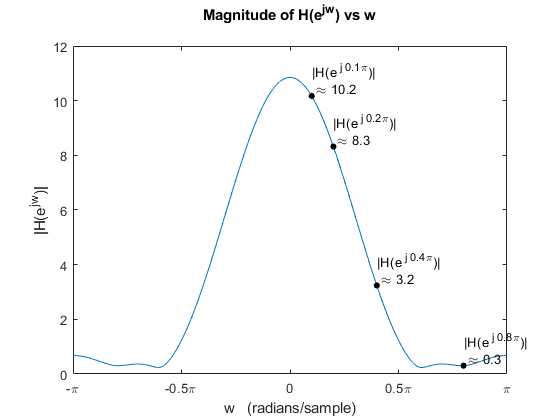


% obtain frequency response H(w) expression from H(z)
% by substituting z = e^(jw)
syms w_;
Hw = subs(Hz, {z}, {exp(1i*w_)});

% compute frequency response H(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hw = subs(Hw, {w_}, {w});
Hw = double(Hw);

% obtain magnitude and phase of H(w)
Hw_mag = abs(Hw);
Hw_arg = phase(Hw);                 % unwrapped phase (in radians)
Hw_ARG = angle(Hw);                 % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of H(w) vs w
fig = figure; 
plot(w, Hw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H(e^{jw})|');
title({'Magnitude of H(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hw_mag, dw, [], 0.65, {'|H(e^{ j ', '\pi})|', ''}, pi);

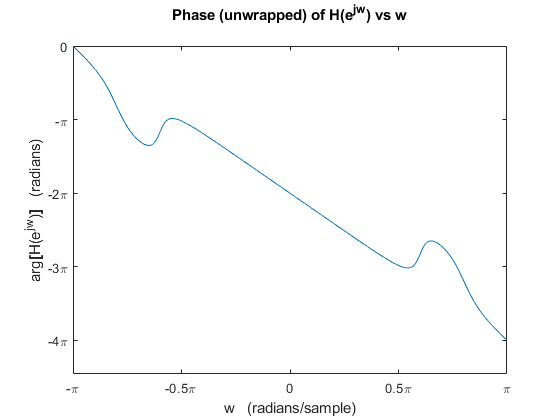


% plot phase (unwrapped) of H(w) vs w
fig = figure; 
plot(w, Hw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

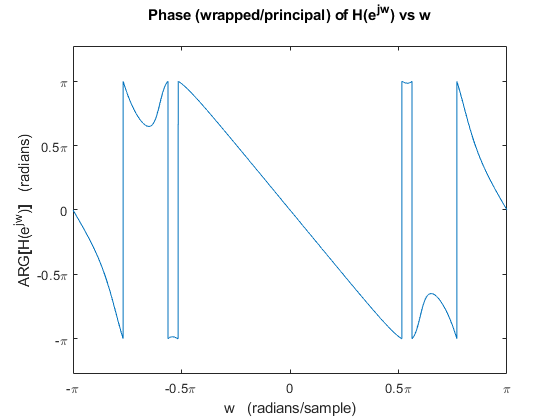


% plot phase (wrapped/principal) of H(w) vs w
fig = figure; 
plot(w, Hw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

Now, the group delay for $H\left(e^{j\omega \;} \right)$ is given by,


$$\tau \left(\omega \right)\;=\;\textrm{grd}\left\lbrack H\left(e^{j\omega } \right)\right\rbrack \;=\;-\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace$$


where the derivative of (unwrapped) phase may be computed using,


$$\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace \;=\;\lim_{\Delta \omega \;\to \;0} \frac{\arg \left\lbrack H\left(e^{j\;\left(\omega \;+\;\Delta \omega \right)} \right)\right\rbrack -\arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack }{\Delta \omega }$$


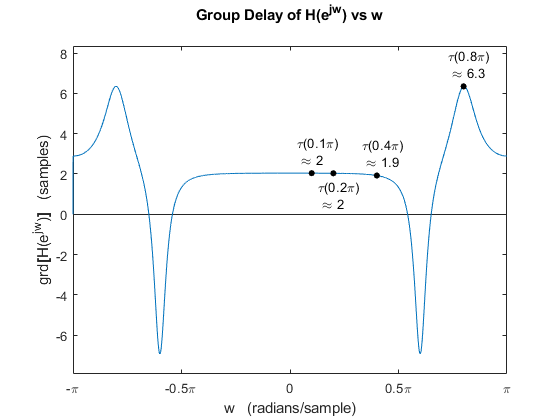


% <task> plot group-delay of given LTI system

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of H(w)
Hw_grd = -([Hw_arg 0]-[0 Hw_arg])/dw;
Hw_grd = Hw_grd(1:(length(Hw_grd)-1));

% plot group-delay of H(w) vs w
fig = figure; 
plot(w, Hw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hw_grd)-1 max(Hw_grd)+2]);
markOnPlot(wvals, w, Hw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);

**Question (2):**

Is the system stable? Is the system causal?

**Answer (2):**

Consider the pole-zero plot of this system $H\left(z\right)$, as drawn below.

% extract CCDE coefficients (b's and a's) from H(z) expression
[N, D] = numden(Hz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    1.0000    2.5788    3.4975    2.5074    1.2656

a =
     1     0     0     0     0



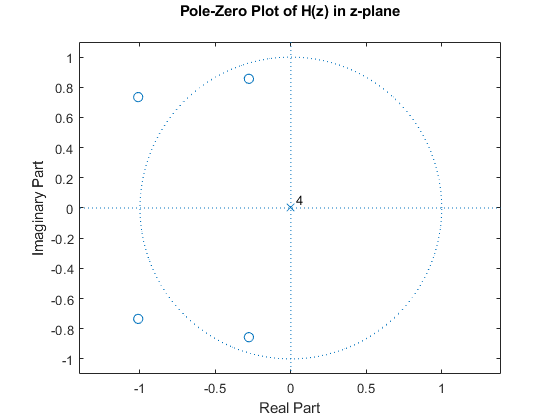


% plot the pole-zero map of H(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H(z) in z-plane';''});

As can be seen above, all poles of $H\left(z\right)$ lie within the unit-cricle. Furthermore, all 4 poles lie at origin. This means the only possible ROC is the one extending outward from $|z|>0$. So, ROC is all of z-plane except $z=0$.

Since the unit-circle lies in ROC, the system is stable. As here, ROC extends outward from outermost pole ($z=0$), so $h\left\lbrack n\right\rbrack$ is a right-sided function (possibly with $h\left\lbrack n\right\rbrack =0\;\;\forall \;\;n<0$). Hence the system is also causal.

So the system represented by $H\left(z\right)$ is causal and stable.

**Question (3):**

Pass $x\left\lbrack n\right\rbrack$ through $H\left(z\right)$ for $\omega_c =0\ldotp 1\pi ,\;0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 8\pi$ and obtain the output signal $y\left\lbrack n\right\rbrack$. 

How does the magnitude of the output signal change with change in $\omega_c$? Can you explain the difference in magnitude corresponding to different $\omega_c$ using the magnitude response of $H\left(z\right)$.

**Answer (3):**

Since MATLAB defines $\textrm{sinc}\left(\right)$ function as $\textrm{sinc}\left(x\right)=\frac{\sin \left(\pi x\right)}{\pi x}$, we'll define $x\left\lbrack n\right\rbrack$ as, $x\left\lbrack n\right\rbrack \;=\;\textrm{sinc}\left(\frac{n-50}{16}\right)\;\cos \left(\omega_c \;n\right)$, i.e. without the extra $\pi$ in MATLAB.

Note that in frequency-domain, this $\textrm{sinc}\left(\right)$ function corresponds to a gate-pulse of certain width ($W$), which is shift-copied to $\omega =\pm \;\omega_c \;\textrm{rad}/\textrm{sample}$ due to the $\cos \left(\right)$ term. Changing $\omega_c$ in $x\left\lbrack n\right\rbrack$ thus changes where the gate-pulse (+ve & -ve) is centered in $x\left\lbrack n\right\rbrack$'s spectrum.

The code, along with the results, to pass $x\left\lbrack n\right\rbrack$ for each $\omega_c$ through $H\left(z\right)$, starts below.

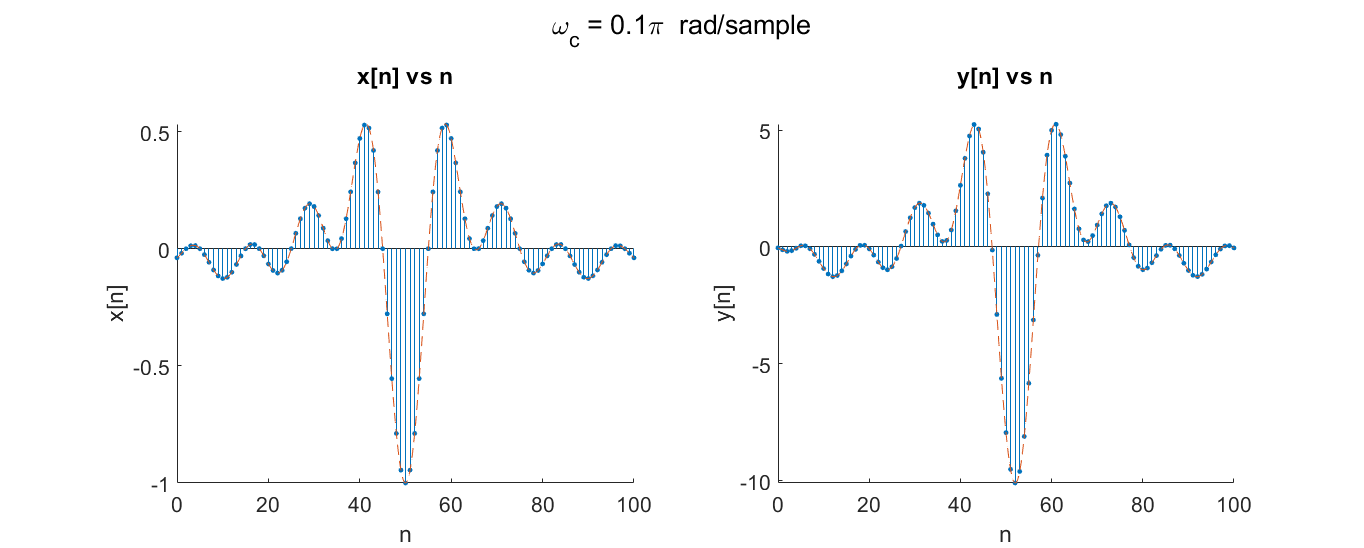

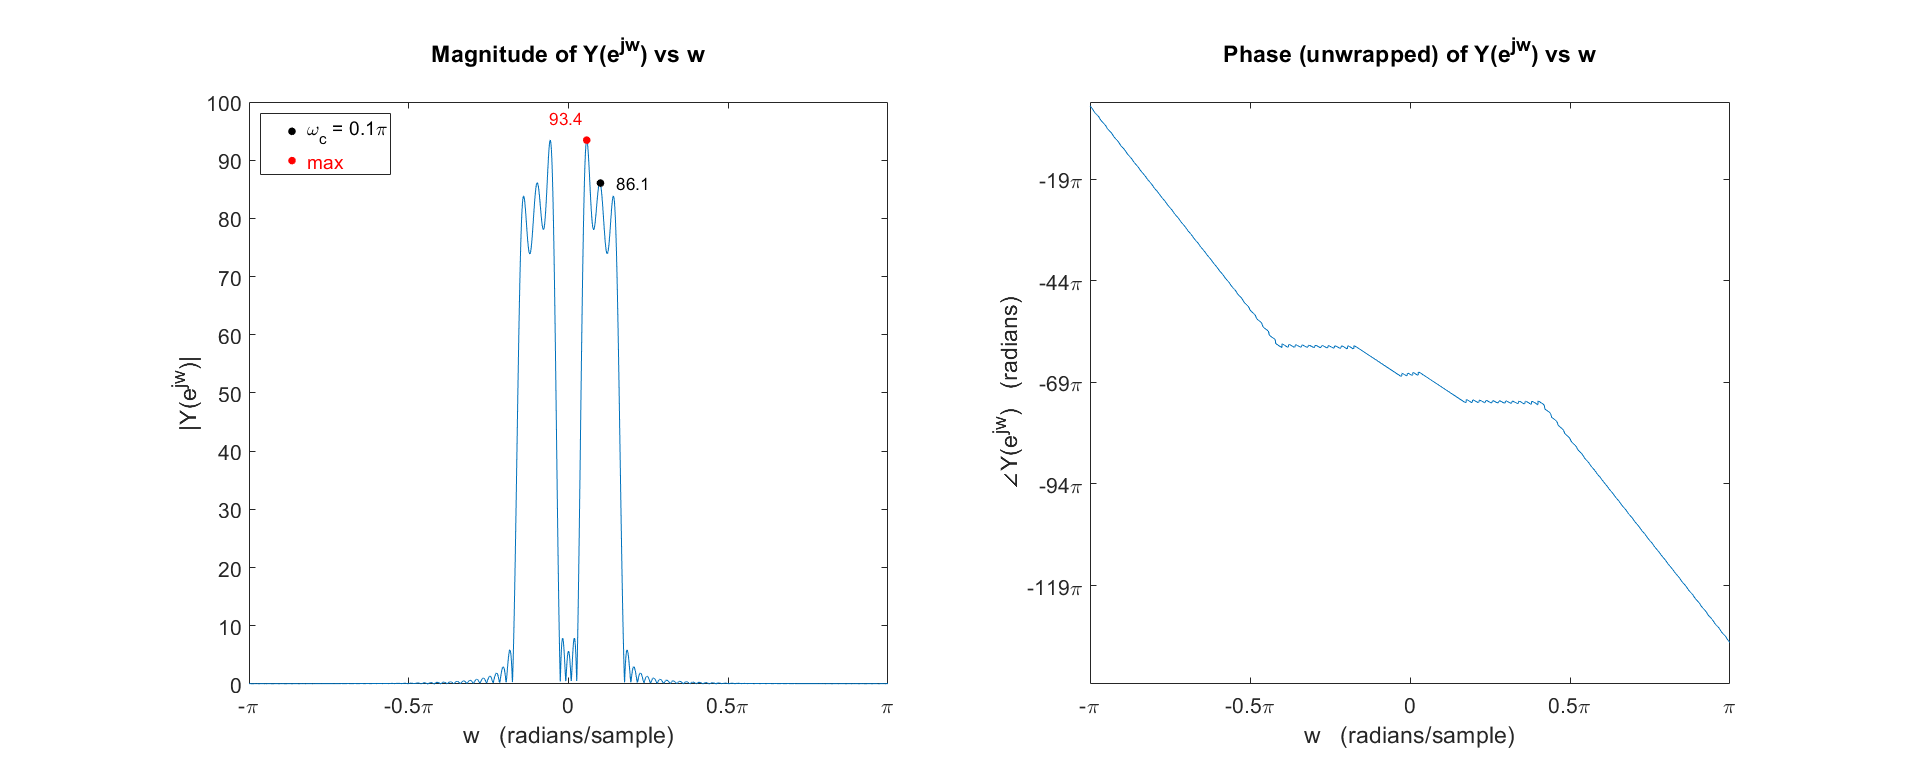

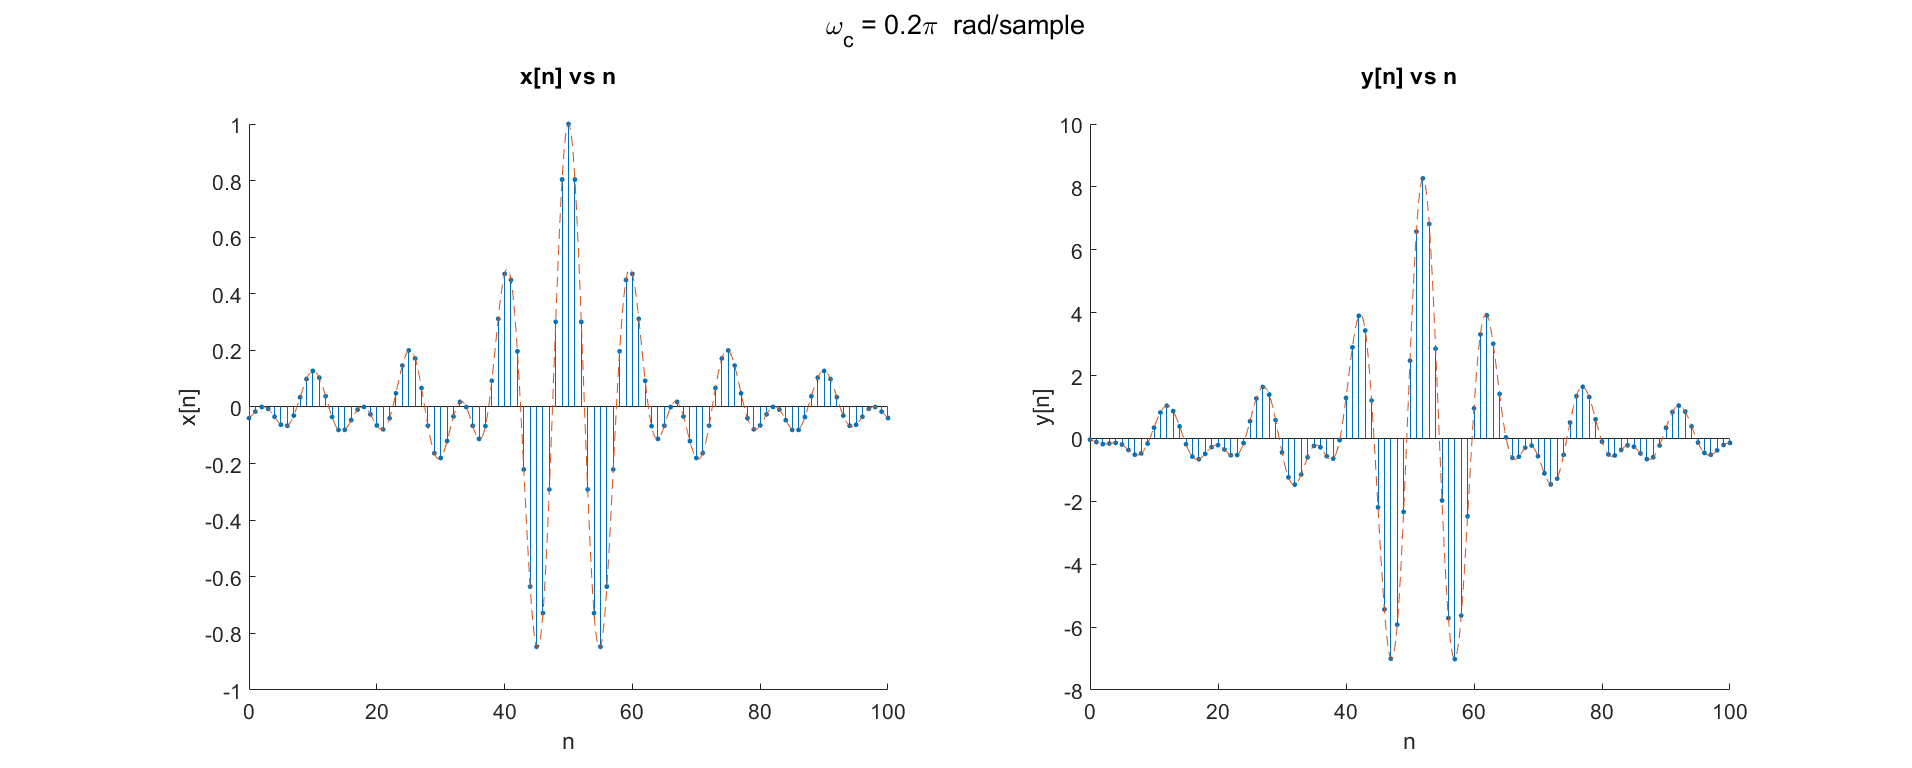

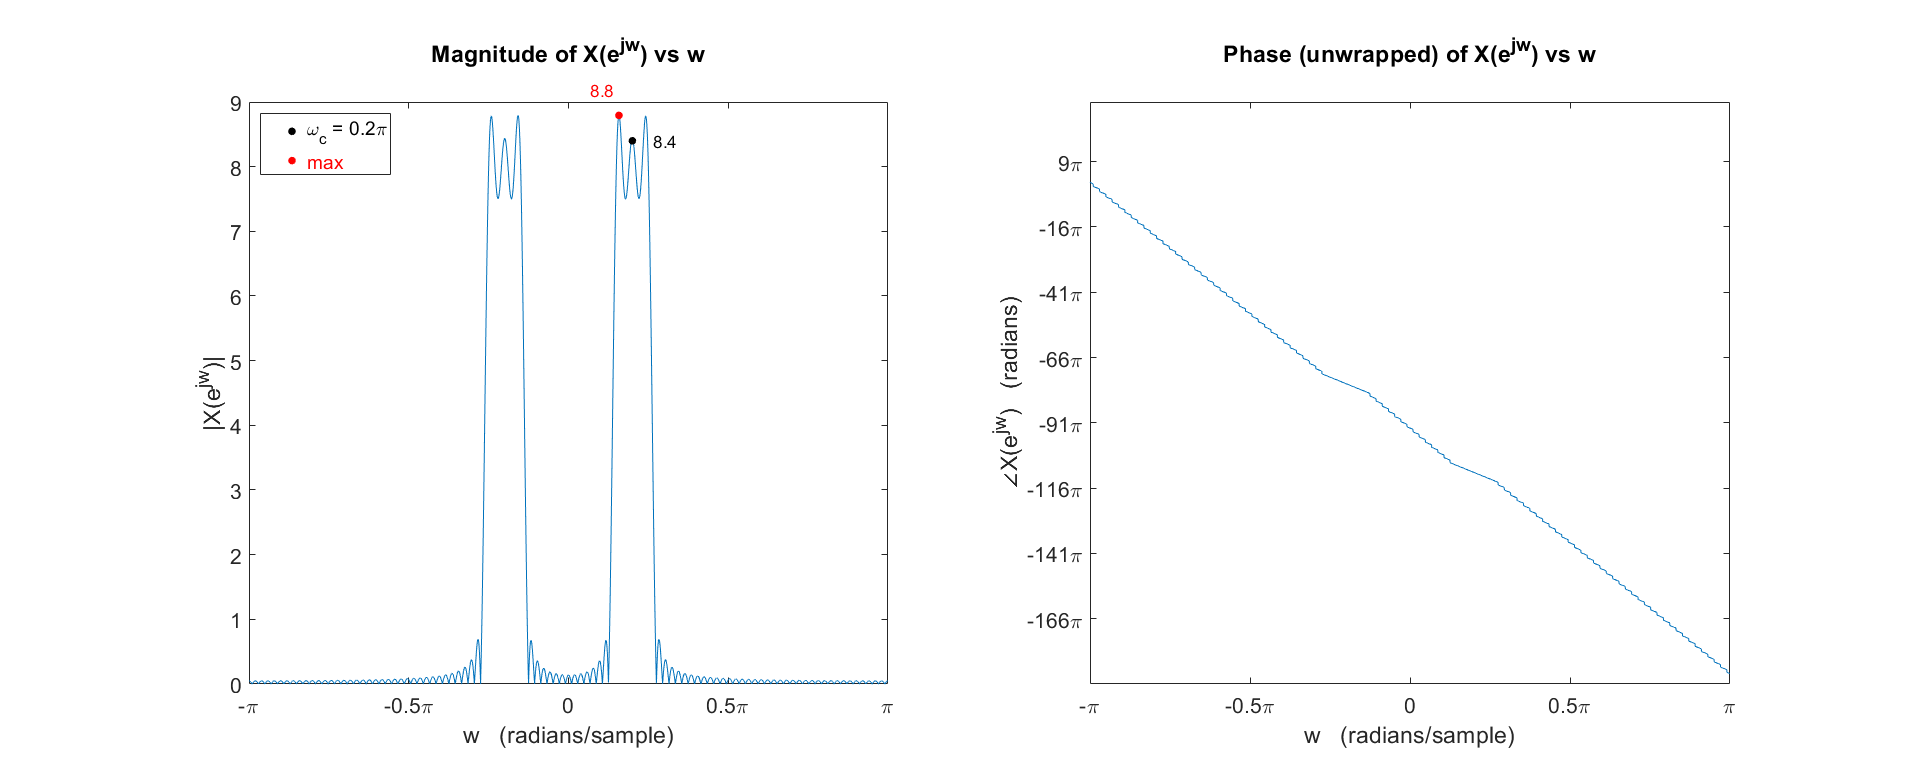

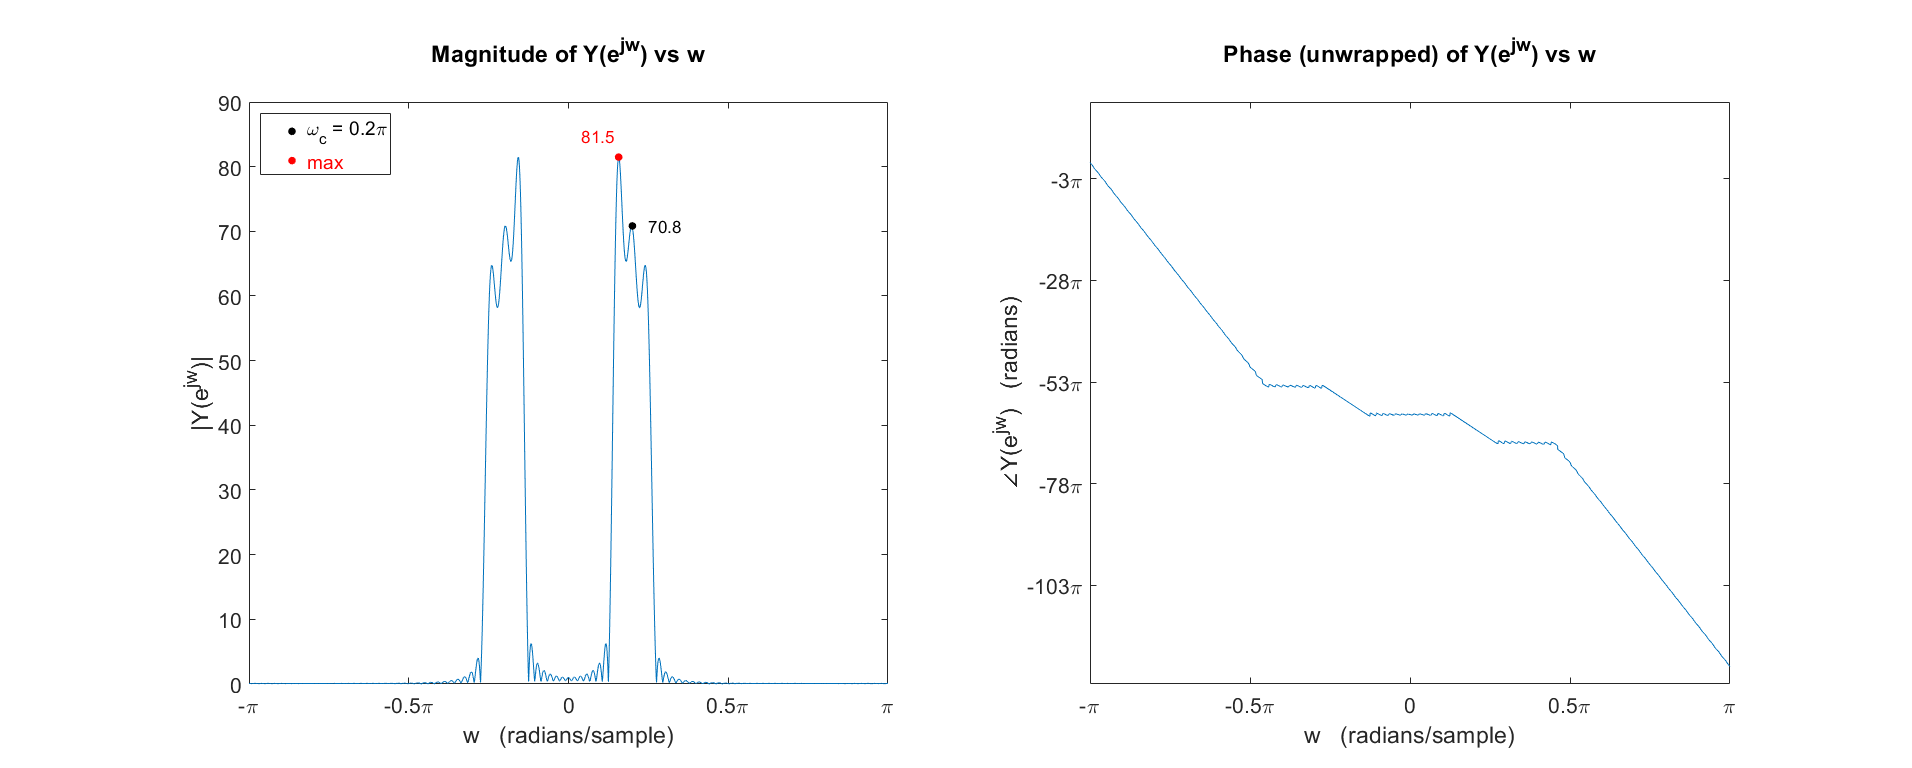

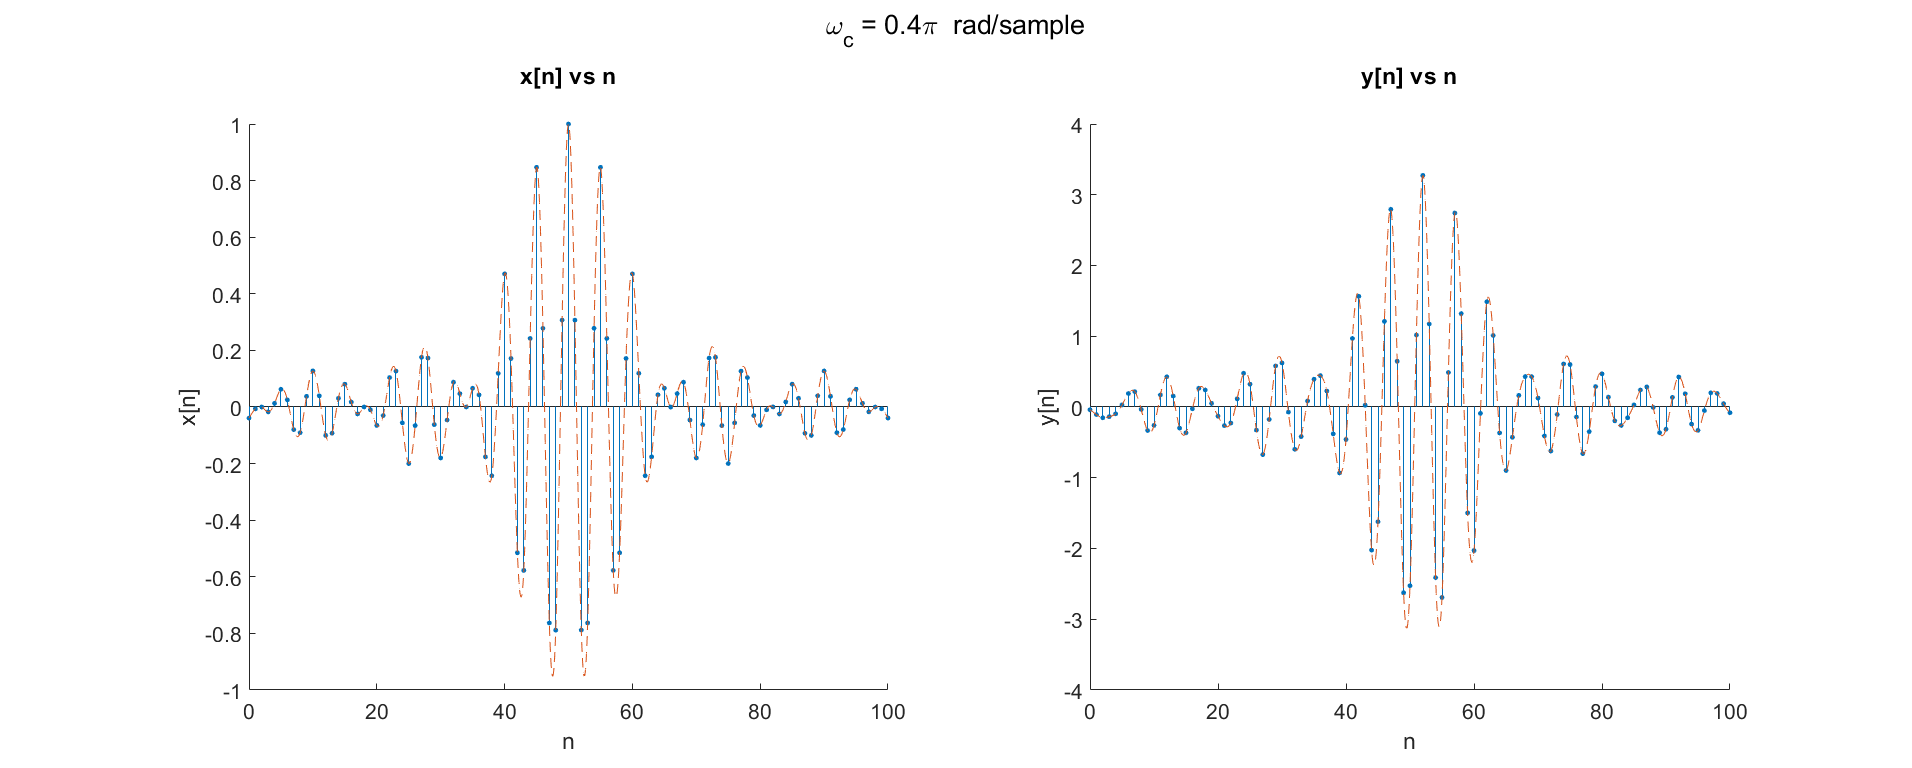

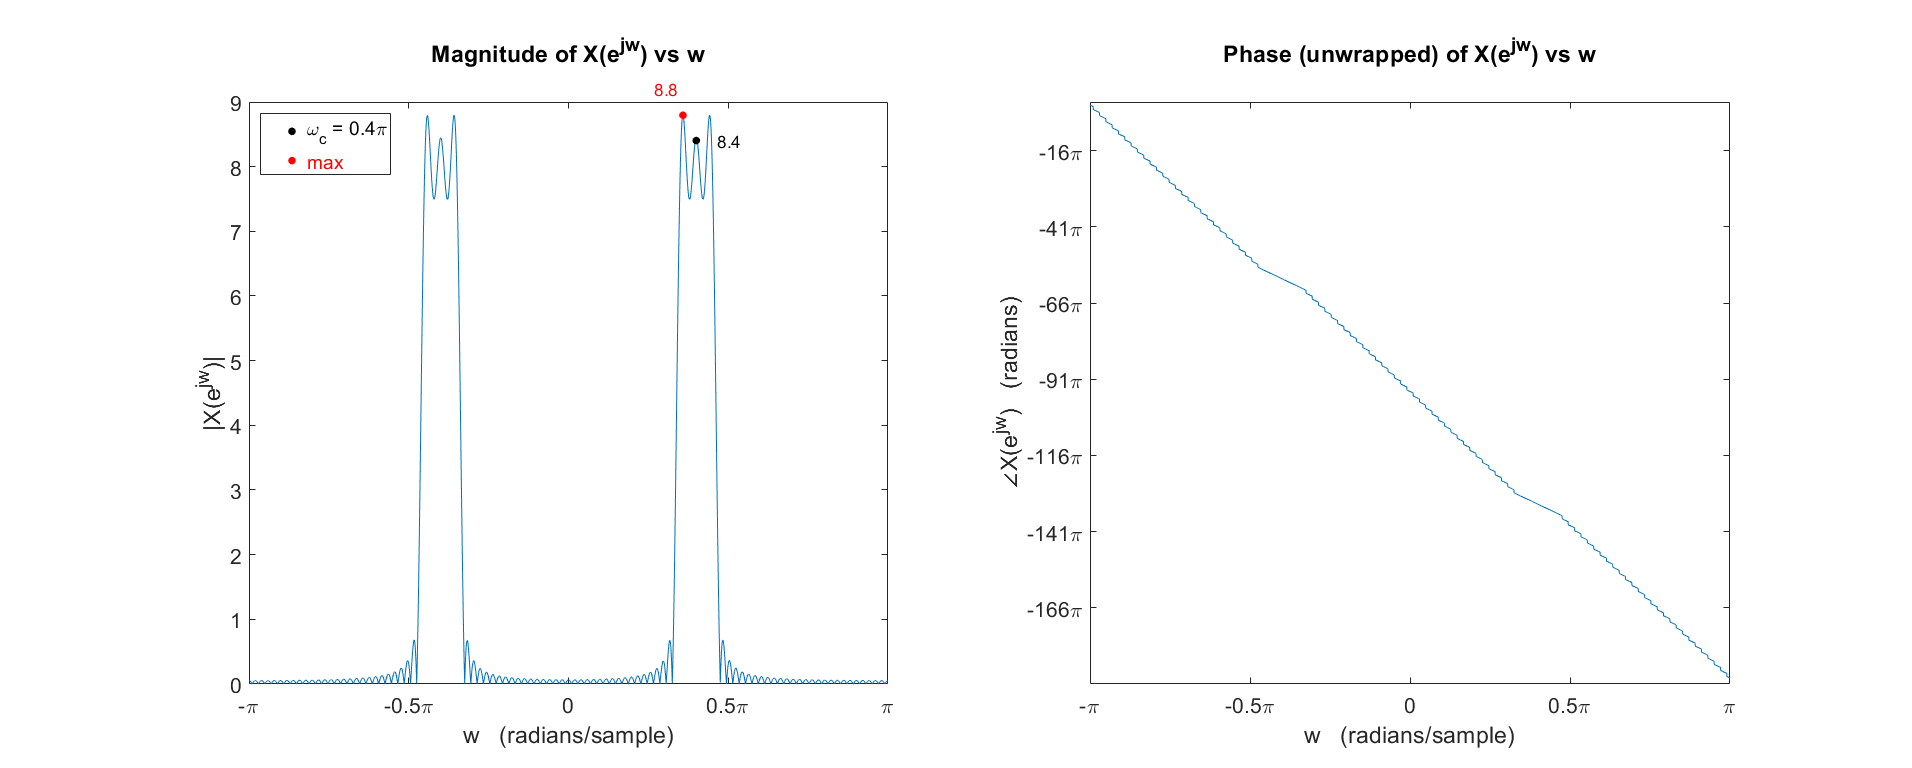

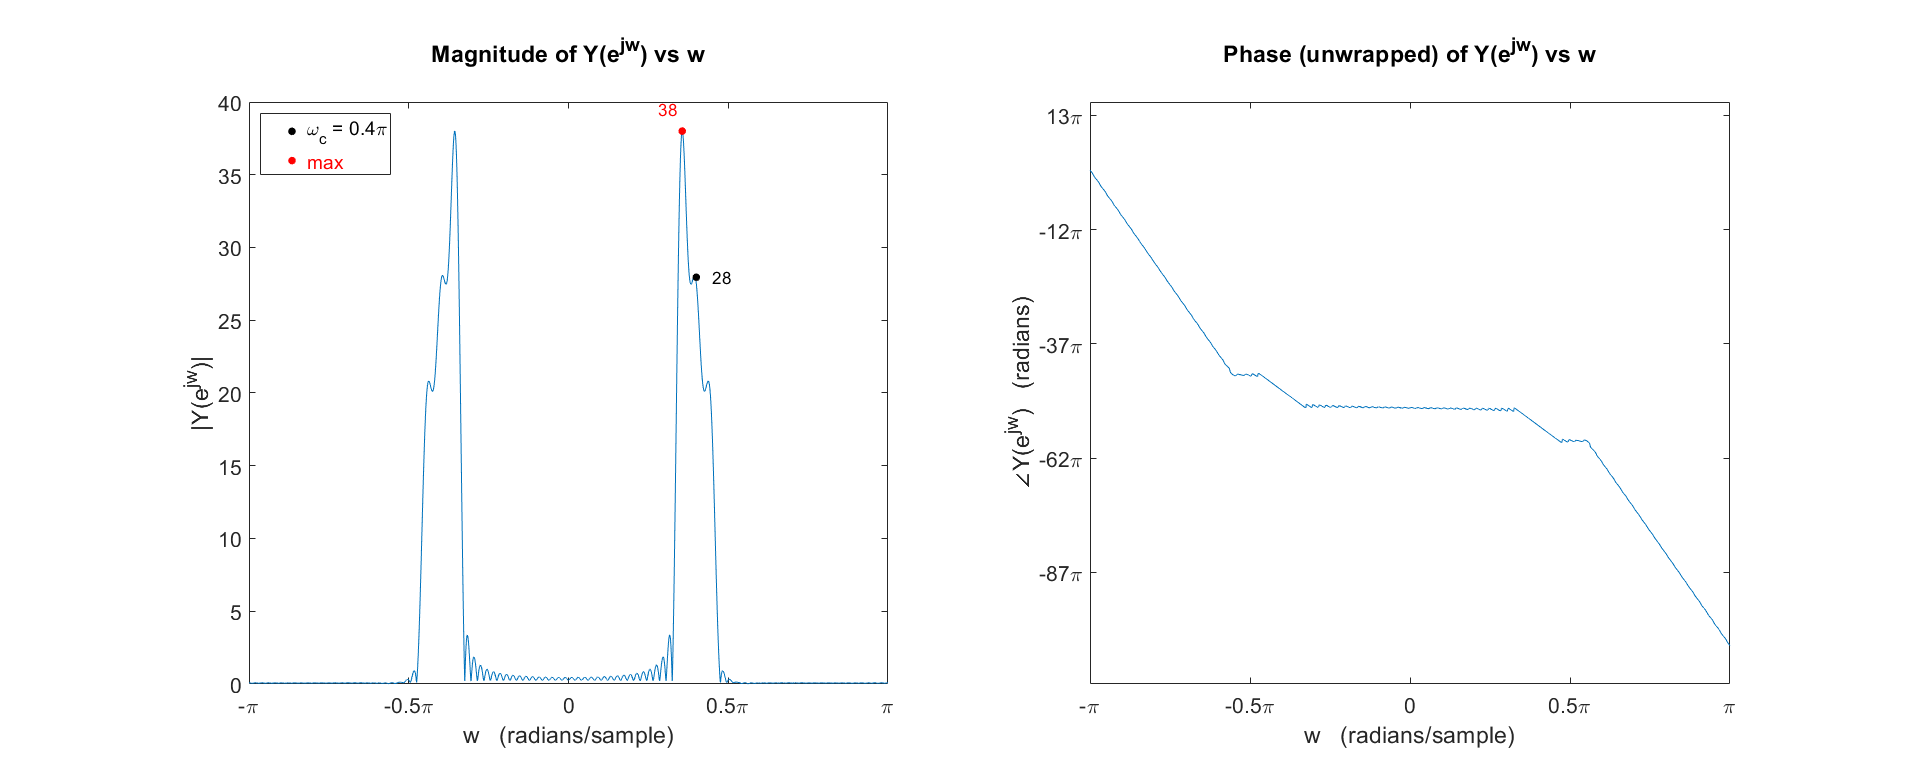

% <task> pass x[n] (for each wc value) through system H(z),
% and plot the output y[n] and its spectrum

wcvals = [0.1, 0.2, 0.4, 0.8]*pi;           % wc values (x[n] center frequencies)
n = 0:100;
x = cell(1, length(wcvals));                % to store x[n] arrays for different wc
y = cell(1, length(wcvals));                % to store y[n] arrays for different wc
ny = cell(1, length(wcvals));               % to store ny arrays for different wc

for i = 1:length(wcvals)
    
    % define x[n] = (sin(pi*(n-50)/16)./(pi*(n-50)/16)).*cos(wc*n)
    wc = wcvals(i);
    x{i} = sinc((n-50)/16).*cos(wc*n);
  
    % compute DTFT X(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Xw = x{i} * exp(-1i * n' * w);          % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT X(w)
    Xw_mag = abs(Xw);
    Xw_arg = phase(Xw);
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % compute output y[n], with input x[n] to system represented by H(z),
    % using get_system_out() and extracted b's and a's
    [y{i}, ny{i}] = get_system_out(b, a, x{i}, N_aux, M_init);
    
    % compute DTFT Y(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Yw = y{i} * exp(-1i * ny{i}' * w);      % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT Y(w)
    Yw_mag = abs(Yw);
    Yw_arg = phase(Yw);
    
    % plot sequences x[n] & y[n], and their DTFTs X(w) & Y(w) (magnitude and phase)
    plot2SeqDTFT(n, x{i}, wc, w, Xw_mag, Xw_arg, 'x', 'X', ...
        [0.2 0 -0.04 0.4, 0.15 0 -0.04 0.04*max(Yw_mag)], ...
        ny{i}, y{i}, Yw_mag, Yw_arg, 'y', 'Y', 'left', 'right');

end

In the magnitude plot of $H\left(e^{j\omega } \right)=H\left(\omega \right)$ (Page 3), the magnitude values i.e. gains for each of the $\omega_c$ frequencies have been marked. These gain values are as follows:


$$\begin{array}{l}
|H\left(\;\;\;0\ldotp 1\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;10\ldotp 2\\
|H\left(\;\;\;0\ldotp 2\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;8\ldotp 3\\
|H\left(\;\;\;0\ldotp 4\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;3\ldotp 2\\
|H\left(\;\;\;0\ldotp 8\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3
\end{array}$$


Since $H\left(z\right)$ is not an all-pass system, the various frequency components (cantered around $\omega_c$) in $x\left\lbrack n\right\rbrack$ are distorted (in magnitude) by different amounts. Following table summarizes the variation in magnitude from $X\left(e^{j\omega } \right)$ to $Y\left(e^{j\omega } \right)$ after being passed through $H\left(z\right)$:


$$\matrix{\cr
\text{ }    	&|X(e^{j\omega})|	&|Y(e^{j\omega})| & \frac{|Y(e^{j\omega})|}{|X(e^{j\omega})|}=|H(e^{j\omega})|\cr
& \text{---------------------------------} & \text{---------------------------------}& \text{---------------------------------}  \cr
\text{center frequency of x[n] \,\,\,} (\omega_c) & \matrix{\text{at }\omega_c &&&& \text{max}} &  \matrix{\text{at }\omega_c &&&& \text{max}}  &  \matrix{\text{at }\omega_c &&&& \text{max}}\cr
\text{--------------------------------------------}  & \text{----------------------------------} & \text{---------------------------------} & \text{---------------------------------}  \cr
0.1\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{86.1 \;\;\;\;\;\;\;\;\;\;\;\; 93.4}}		& \matrix{\text{10.3 \;\;\;\;\;\;\;\;\;\;\;\; 10.6}}	\cr
0.2\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &   \matrix{\text{70.8 \;\;\;\;\;\;\;\;\;\;\;\; 81.5}}		& \matrix{\text{\;\;8.4  \;\;\;\;\;\;\;\;\;\;\;\; 9.26}} \cr
0.4\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;\;28 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 38}}	&  \matrix{\text{\;\;3.3 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 4.3}} \cr
0.8\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;2.6 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 3.3}}       &  \matrix{\text{\;\;0.3 \;\;\;\;\;\;\;\;\;\;\;\; 0.38}}\cr
}
$$


The ratio of output to input magnitude (shown in the last 2 columns of above table) corresponds to the gain provided by the system $H\left(z\right)$ to the input. Note that the gain values at center frequencies $\omega_c$, calculated above, match (approximately) with the magnitude values noted further above from the $|H\left(e^{j\omega \;} \right)|$ plot at respective frequencies. Thus the output magnitude is given by,


$$|Y\left(e^{j\omega } \right)|\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|$$


And since $H\left(e^{j\omega } \right)$ has different (widely-varying) magnitudes at different frequencies $\omega$, this explains the changing magnitude of output $Y\left(e^{j\omega \;} \right)$ based on the frequency-content in input $X\left(e^{j\omega } \right)$ (centered around $\pm \;\omega_c$).

*Next Question/Answer starts from the next page.*

**Question (4.a):**

Design a causal, stable magnitude inverse of the system. Draw magnitude, phase and group delay response of the inverse sytem.

**Answer (4.a):**

$H\left(z\right)$ (stable & causal) is a non-minimum-phase system (doesn't have all poles and zeros inside unit circle), so its rational inverse $1/H\left(z\right)$ is not stable & causal. But, any system $H\left(z\right)$ can be decomposed into minimum-phase $H_{\min } \left(z\right)$ and all-pass $H_{\textrm{ap}} \left(z\right)$ systems, as follows:


$$H\left(z\right)\;=\;H_{\min } \left(z\right){\;H}_{\textrm{ap}} \left(z\right)$$


where $H_{\min } \left(z\right)$ has all its poles and zeros inside the unit-circle, that is, it and it's inverse ($1/H_{\min } \left(z\right)$) are stable & causal; while $H_{\textrm{ap}} \left(z\right)$ has constant (unity) magnitude. In terms of magnitude, $H_{\textrm{ap}} \left(z\right)$ does not have any contribution, hence the magnitude distortion in $H\left(z\right)$ comes from $H_{\min } \left(z\right)$. 

So, to compensate for this magnitude distortion, we may use the system given by $1/H_{\min } \left(z\right)$ — which will be a casual and stable magnitude inverse of $H\left(z\right)$. We'll call the inverse system $H_{\textrm{inv}} \left(z\right)$, given as,


$$H_{\textrm{inv}} \left(z\right)\;=\;\frac{1}{H_{\min } \left(z\right)}$$


First, we decompose $H\left(z\right)$ into $H_{\min \left(\right.} \left(z\right)$ and $H_{\textrm{ap}\left(\right.} \left(z\right)$. $H\left(z\right)$ has two zeros outside the unit-circle (at $a_2 =1\ldotp 25e^{j\;0\ldotp 8\pi }$ and $a_2^{\ast } =1\ldotp 25e^{-j\;0\ldotp 8\pi }$). So, first place a zero and a pole at conjugate-reciprocal positions ($0\ldotp 8e^{\mp j\;0\ldotp 8\pi }$) of these zeros. This does not change overall $H\left(z\right)$ as the pole & zero cancel out to give original $H\left(z\right)$. So, we have,


$$H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}$$


From this expression, we can extract an all-pass system of the form with 1 complex-conjugate pole-zero pair,


$$H_{\textrm{ap}} \left(z\right)=\frac{\left(z^{-1} -{e_k }^{\ast } \right)\left(z^{-1} -e_k \right)}{\left(1-e_k {\;z}^{-1} \right)\left(1-e_k^{\ast } {\;z}^{-1} \right)}$$


by keeipng the new zeros (inside unit-circle) in $H_{\min } \left(z\right)$ and putting the outside zeros along with new inside poles into the $H_{\textrm{ap}} \left(z\right)$ part,


$$\begin{array}{l}
H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}\\
\;\;\;\;\;\;\;\;\;\;\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{{\left(1\ldotp 25\right)}^2 \left(0\ldotp 8z-e^{j\;0\ldotp 8\pi } \right)\left(0\ldotp 8z-e^{-j\;0\ldotp 8\pi } \right)}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}\ldotp \frac{z^{-2} \left(e^{-j\;0\ldotp 8\pi } \right)\left(e^{j\;0\ldotp 8\pi } \right)}{z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;=\;{\left(1\ldotp 25\right)}^2 \frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{z^4 }\ldotp \frac{\left(0\ldotp 8e^{-j\;0\ldotp 8\pi } -z^{-1} \right)\left(0\ldotp 8e^{j\;0\ldotp 8\pi } -z^{-1} \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}\\
\;\;\;\;\;\;\;\;\;\;\;=\;{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\;\ldotp \;\frac{\left(z^{-1} -0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z^{-1} -0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}
\end{array}$$


And so, the all-pass and minimum-phase parts of the system are respectively,


$$\begin{array}{l}
H_{\textrm{ap}} \left(z\right)\;=\;\frac{\left(z^{-1} -0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z^{-1} -0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}{\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)}\\
\\
H_{\min } \left(z\right)\;=\;{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)
\end{array}$$


Finally, the magnitude inverse system of $H\left(z\right)$ is given by,


$$\begin{array}{l}
H_{\mathrm{inv}} \left(z\right)\;=\;\frac{1}{H_{\min } \left(z\right)}\;=\;\frac{1}{{\left(1\ldotp 25\right)}^2 \left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } z^{-1} \right)\left(1-0\ldotp 8e^{-j\;0\ldotp 8\pi } z^{-1} \right)\left(1-0\ldotp 8e^{j\;0\ldotp 8\pi } z^{-1} \right)}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{z^4 }{{\left(1\ldotp 25\right)}^2 \left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}
\end{array}$$


which is causal & stable since all its poles and zeros lie inside unit circle.

The code, along with results, to compute & plot various responses from $H_{\textrm{inv}} \left(z\right)$ expression above, starts below.

% <task> plot magnitude and phase response of inverse system Hinv(z)

% define z-domain expression (symbolically)
syms z;
a1 = 0.9*exp(1i*0.6*pi);
a2 = 0.8*exp(1i*0.8*pi);
Hinvz_N = z^4;                                                  % numerator of Hinv(z)
Hinvz_D = (1.25^2)*(z-a1)*(z-conj(a1))*(z-conj(a2))*(z-a2);     % denominator of Hinv(z)
Hinvz = Hinvz_N/Hinvz_D;

% display Hinv(z) expression
disp('Hinv(z) = '); disp(vpa(Hinvz, 4))

Hinv(z) = 


$$\frac{z^{4}}{\left(1.562\,z+0.4346-1.337\,\mathrm{i}\right)\,\left(z+0.2781+0.856\,\mathrm{i}\right)\,\left(z+0.6472-0.4702\,\mathrm{i}\right)\,\left(z+0.6472+0.4702\,\mathrm{i}\right)}$$

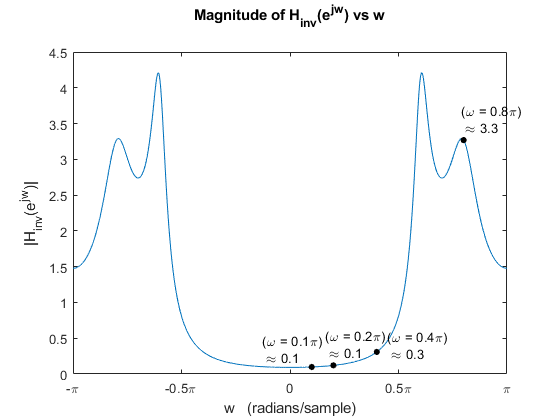


% obtain frequency response Hinv(w) expression from Hinv(z)
% by substituting z = e^(jw)
syms w_;
Hinvw = subs(Hinvz, {z}, {exp(1i*w_)});

% compute frequency response Hinv(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hinvw = subs(Hinvw, {w_}, {w});
Hinvw = double(Hinvw);

% obtain magnitude and phase of Hinv(w)
Hinvw_mag = abs(Hinvw);
Hinvw_arg = phase(Hinvw);           % unwrapped phase (in radians)
Hinvw_ARG = angle(Hinvw);           % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H_{inv}(e^{jw})|');
title({'Magnitude of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hinvw_mag, dw, ...
    [-0.23 -0.04 0.045 -0.01]*pi, [0.25 0.3 0.1 0.3], {'(\omega = ', '\pi)', ''}, pi);

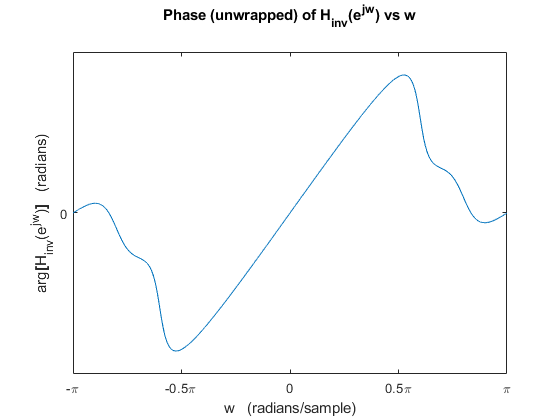


% plot phase (unwrapped) of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H_{inv}(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

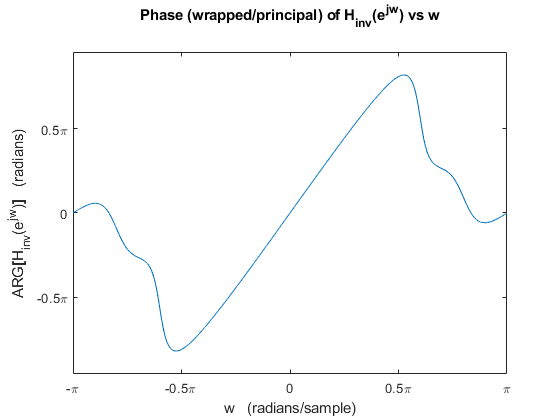


% plot phase (wrapped/principal) of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H_{inv}(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

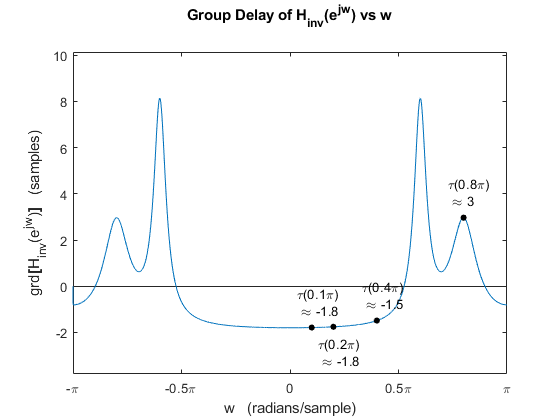


% <task> plot group-delay of given LTI system

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of Hinv(w)
Hinvw_grd = -([Hinvw_arg 0]-[0 Hinvw_arg])/dw;
Hinvw_grd = Hinvw_grd(1:(length(Hinvw_grd)-1));

% plot group-delay of Hinv(w) vs w
fig = figure; 
plot(w, Hinvw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H_{inv}(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H_{inv}(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hinvw_grd)-2 max(Hinvw_grd)+2]);
markOnPlot(wvals, w, Hinvw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);


% extract CCDE coefficients (b's and a's) from Hinv(z) expression
[N, D] = numden(Hinvz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    0.6400         0         0         0         0

a =
    1.0000    1.8507    2.1700    1.4045    0.5184



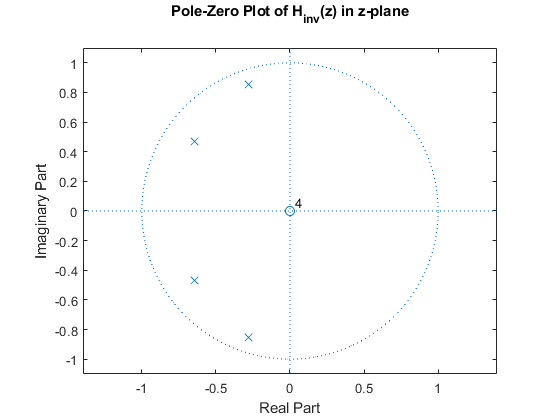


% plot the pole-zero map of Hinv(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H_{inv}(z) in z-plane';''});

As can be seen above, all poles (and zeros) of $H_{\textrm{inv}} \left(z\right)$ lie within the unit-cricle. One possible ROC is that extending outward from outermost pole ($|z|>0\ldotp 9$). If ROC $|z|>0\ldotp 9$ is selected, then the magnitude inverse system is stable as well as causal (right-sided $h\left\lbrack n\right\rbrack$).

**Question (4.b):**

Pass all $y\left\lbrack n\right\rbrack$ obtained in the previous part through the the inverse system.

What is the maximum magnitude of the output of the inverse system? Can you explain the different maximum magnitudes of the output signals corresponding to different $\omega_c$?

Do you think you have gotten exactly the same $x\left\lbrack n\right\rbrack$ at the output of the inverse system? Why or why not?

**Answer (4.b):**

The overall system block diagram will be,

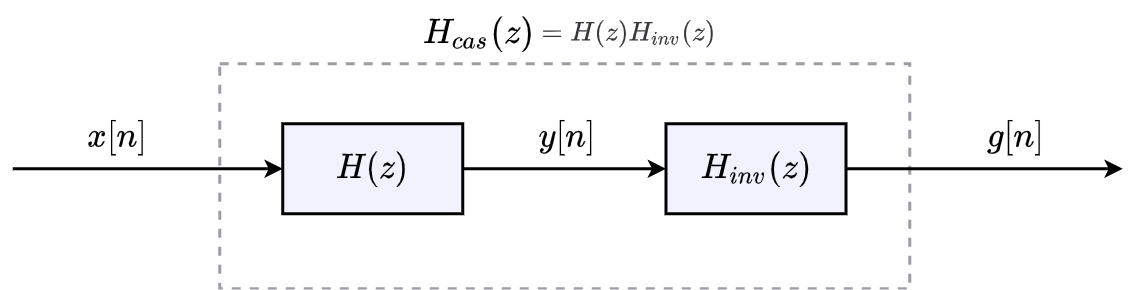

where the output of the magnitude inverse system has been named $g\left\lbrack n\right\rbrack$.

The code, along with the results, to pass $y\left\lbrack n\right\rbrack$ for each $\omega_c$ through $H_{\textrm{inv}} \left(z\right)$, starts below.

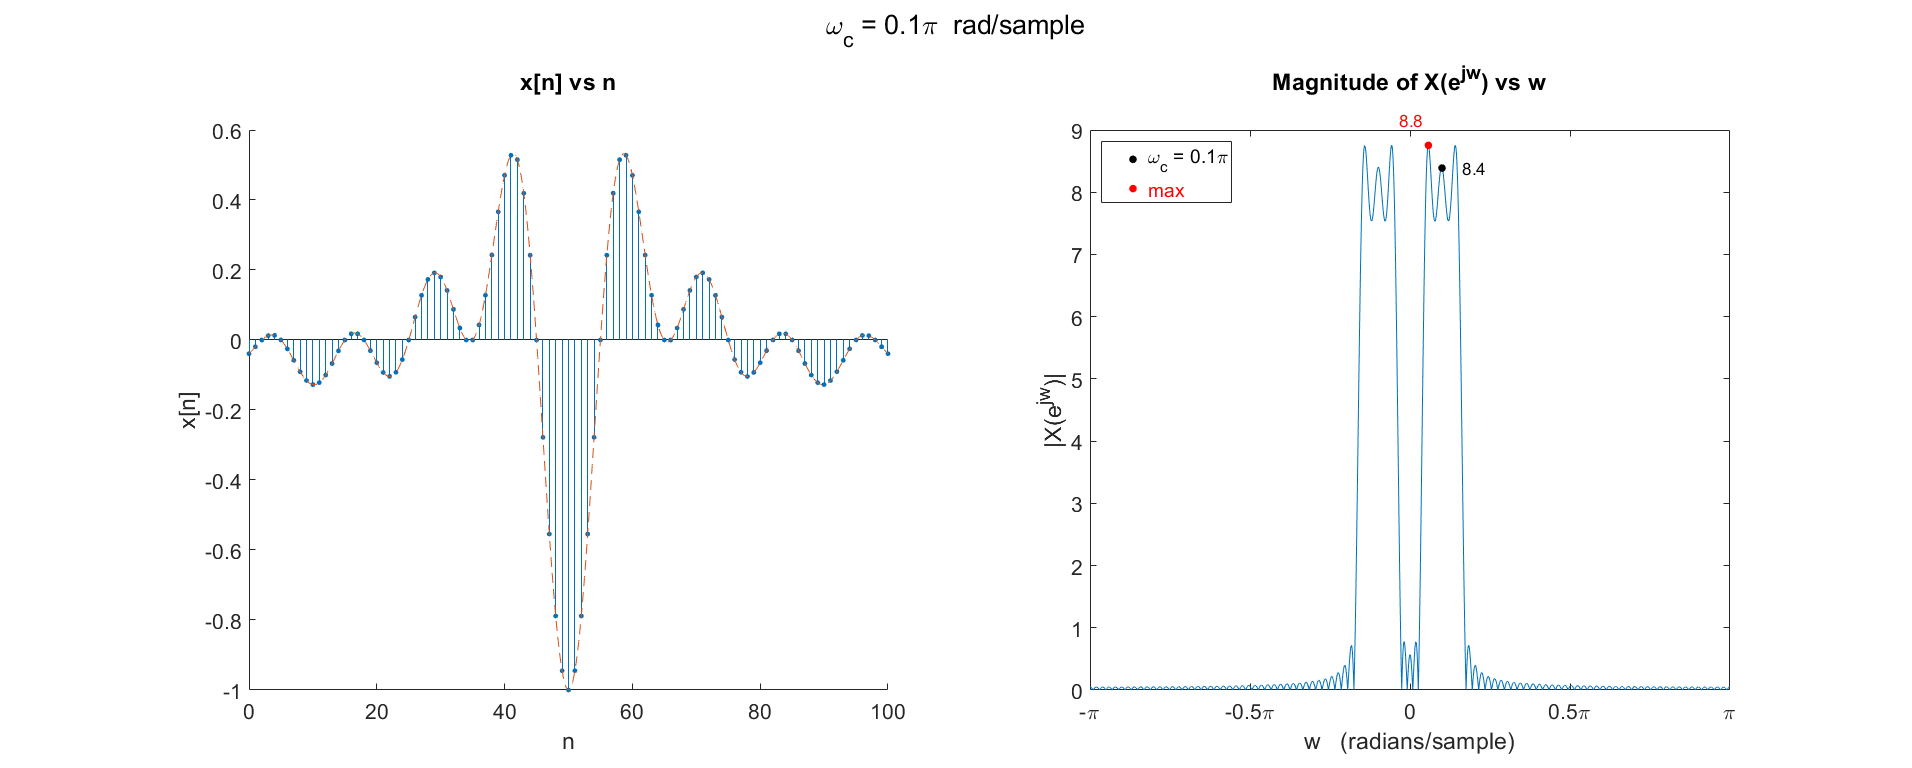

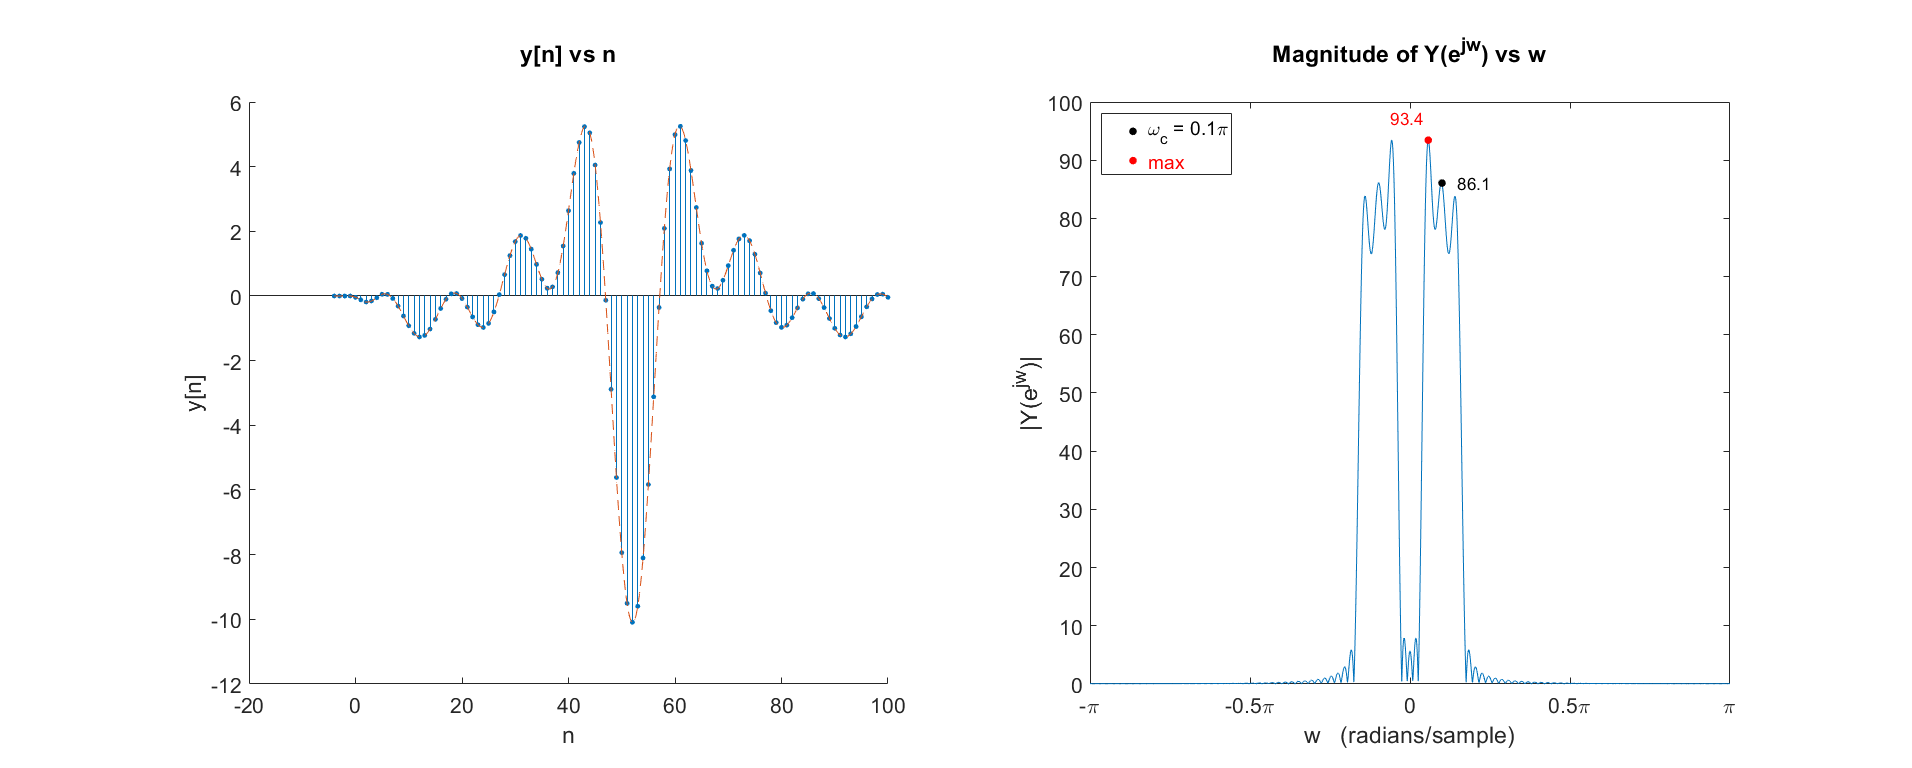

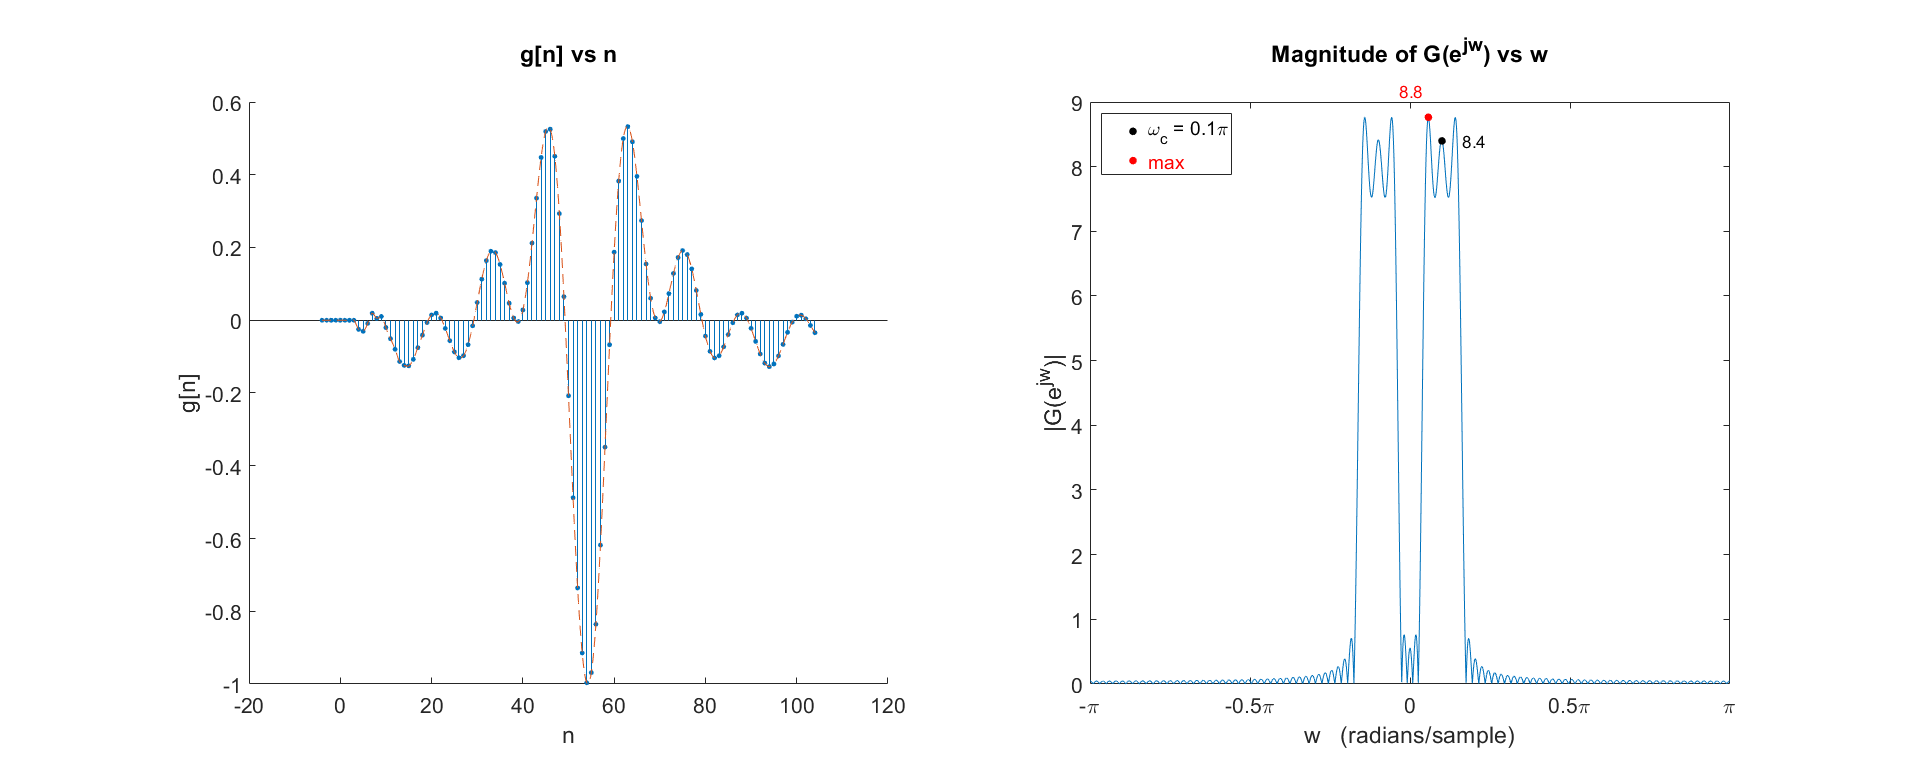

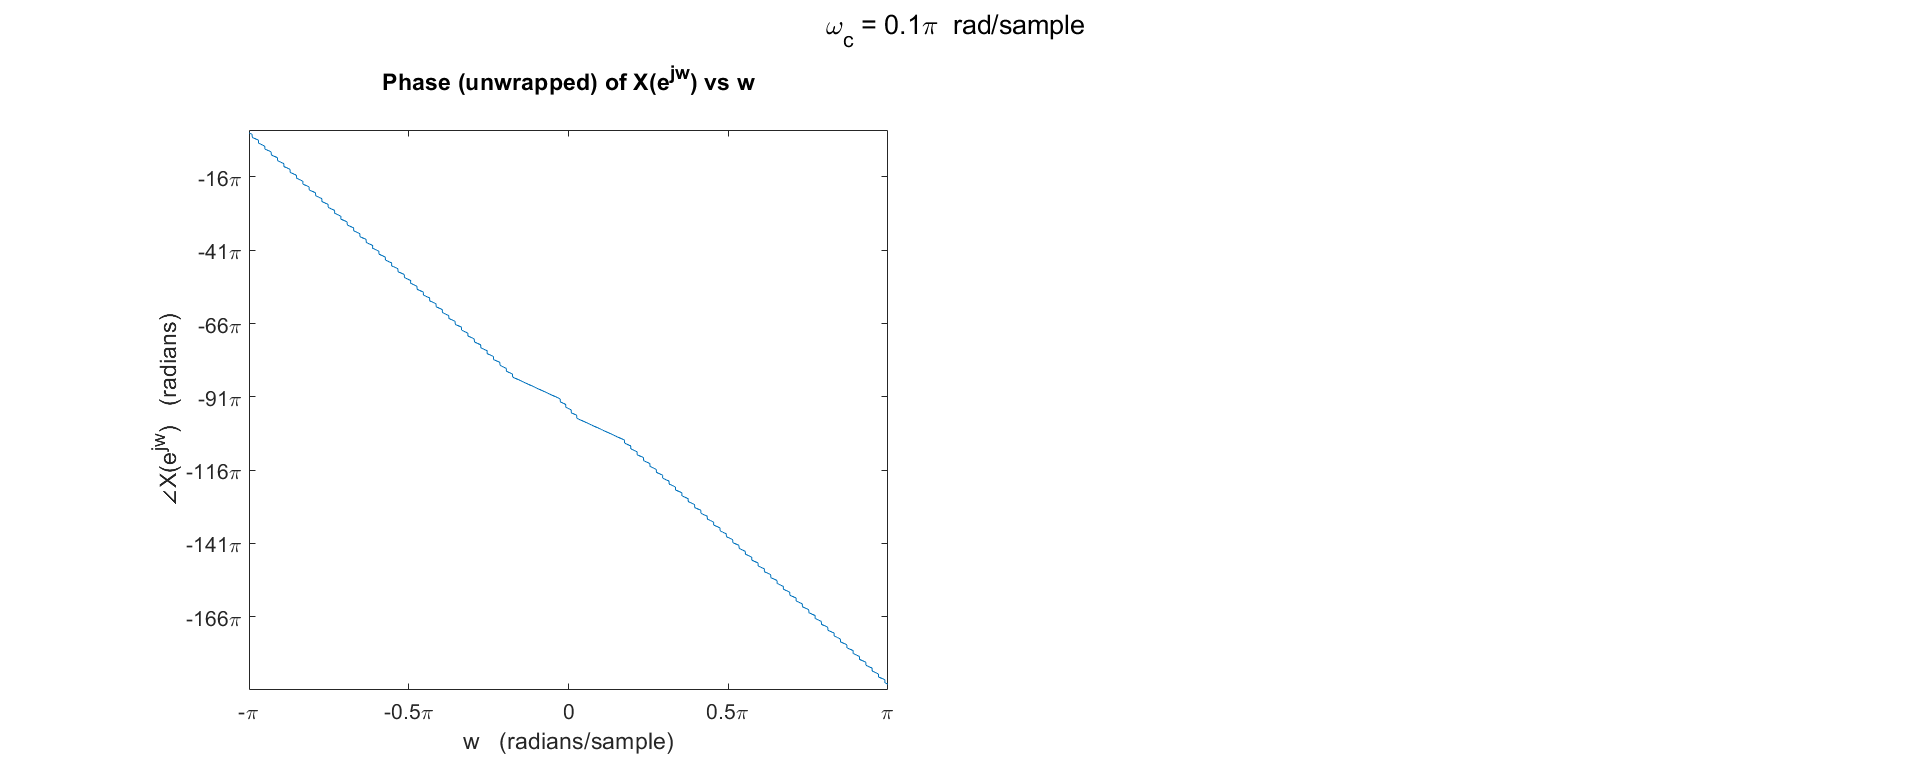

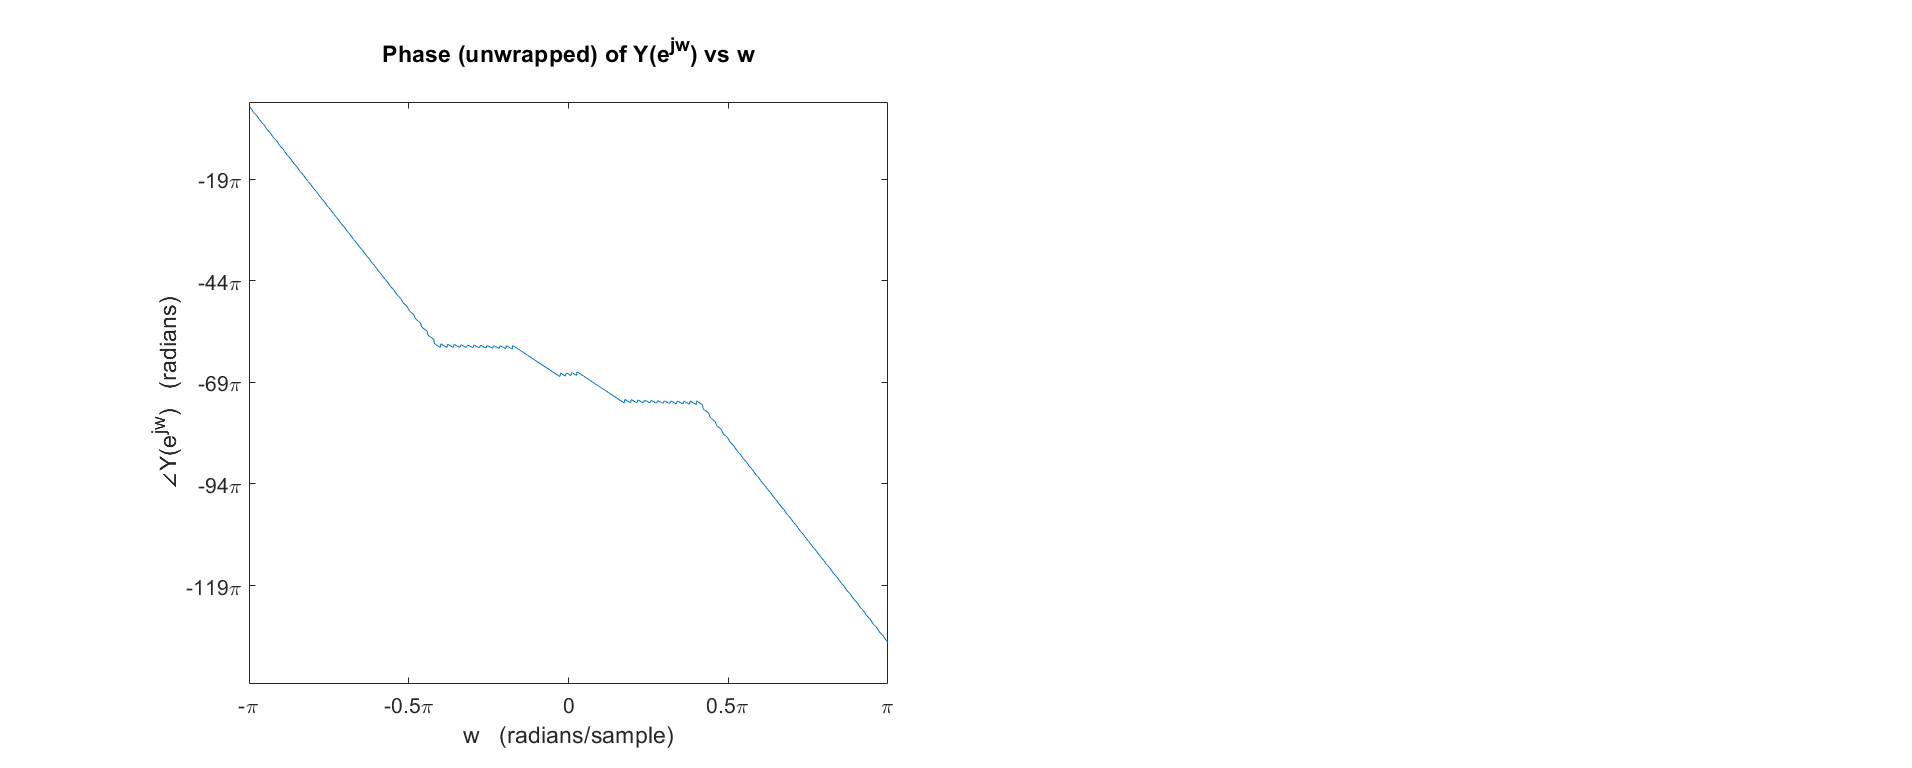

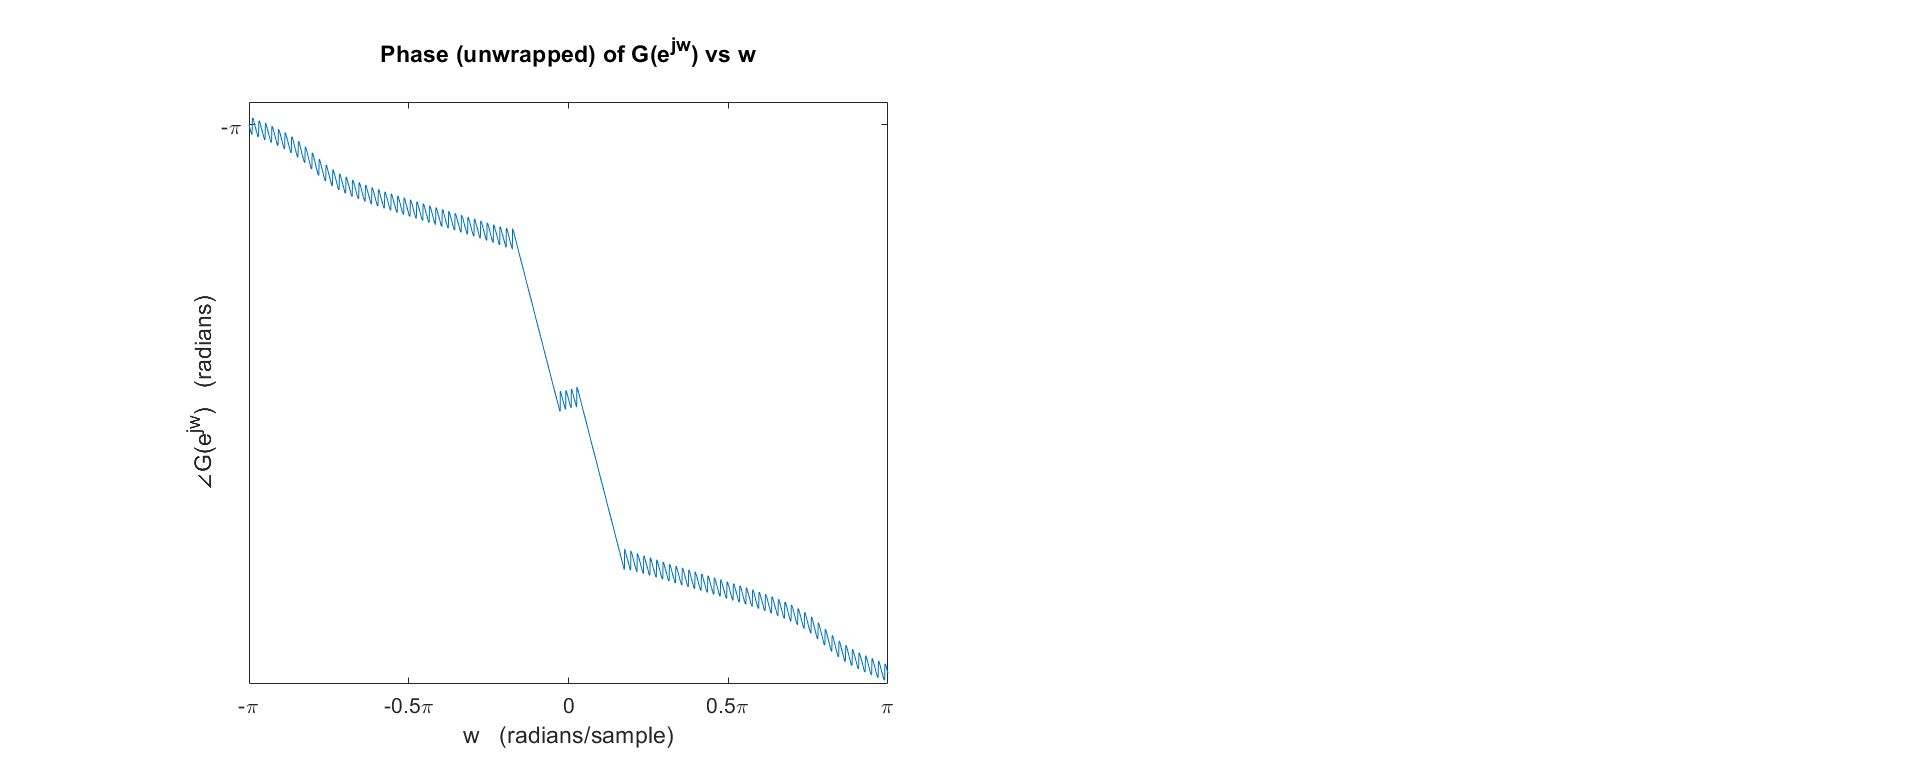

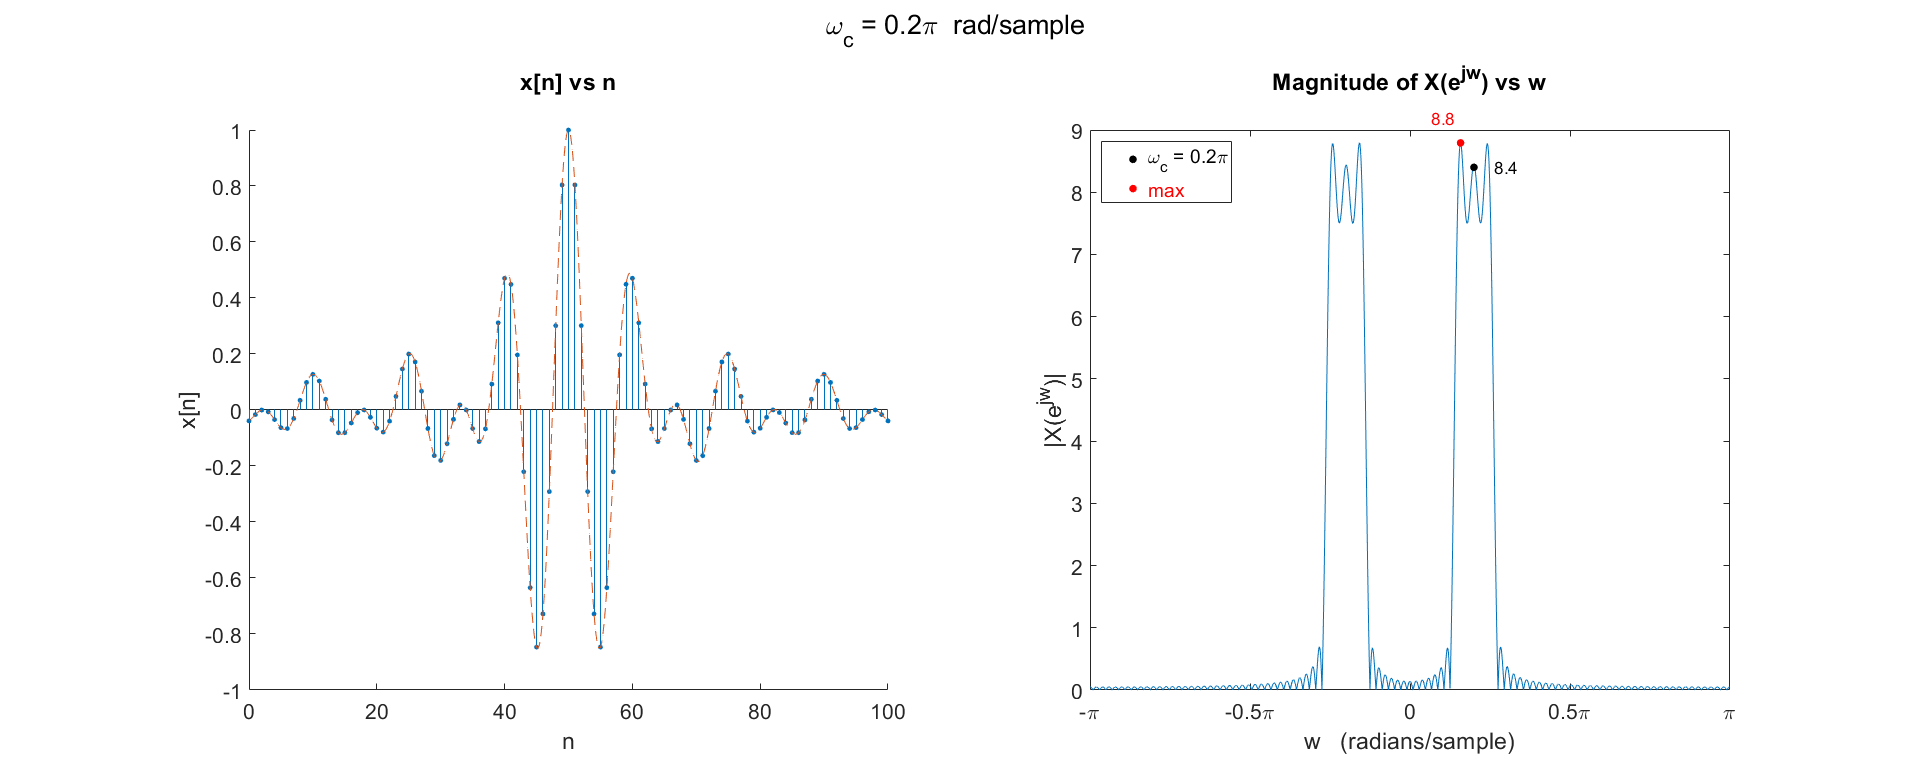

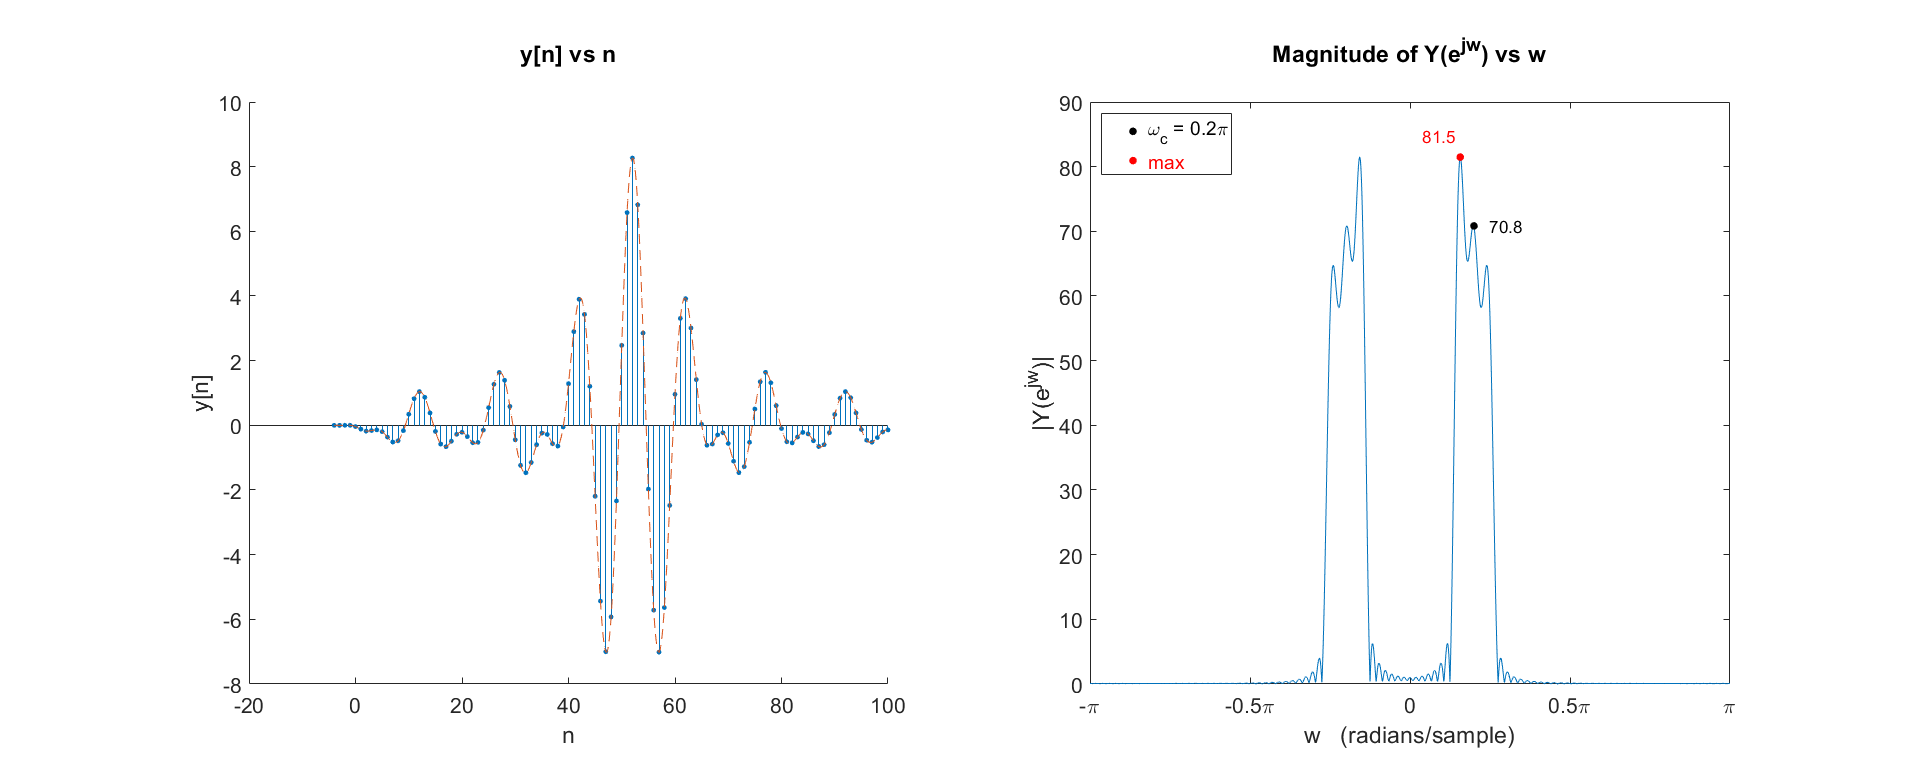

% <task> pass y[n] (for each wc value) through system Hinv(z),
% and plot the output g[n] and its spectrum

wcvals = [0.1, 0.2, 0.4, 0.8]*pi;           % wc values (x[n] center frequencies)
g = cell(1, length(wcvals));                % to store g[n] arrays for different wc
ng = cell(1, length(wcvals));               % to store ng arrays for different wc

for i = 1:length(wcvals)
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % compute output g[n], with input y[n] to system represented by Hinv(z),
    % using get_system_out() and extracted b's and a's
    [g{i}, ng{i}] = get_system_out(b, a, y{i}, N_aux, M_init);
    
    % compute DTFT G(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Gw = g{i} * exp(-1i * ng{i}' * w);      % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT G(w)
    Gw_mag = abs(Gw);
    Gw_arg = phase(Gw);
    
    % compute DTFT X(w) for comparison with G(w)
    Xw = x{i} * exp(-1i * n' * w);          % using matrix-multiplication method
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT X(w)
    Xw_mag = abs(Xw);       Xw_arg = phase(Xw);
    
    % compute DTFT Y(w) for comparison with G(w)
    Yw = y{i} * exp(-1i * ny{i}' * w);      % using matrix-multiplication method
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT Y(w)
    Yw_mag = abs(Yw);       Yw_arg = phase(Yw);
    
    % plot sequences x[n], y[n] & g[n], and their DTFTs' magnitudes
    plot3SeqDTFT({n, ny{i}, ng{i}}, {x{i}, y{i}, g{i}}, wcvals(i), w, ...
        {Xw_mag, Yw_mag, Gw_mag}, {'x', 'y', 'g'}, {'X', 'Y', 'G'}, {Xw_arg, Yw_arg, Gw_arg},...
        {[0.2 0 -0.04 0.4], [0.15 0 -0.04 0.04*max(Yw_mag)], [0.2 0 -0.04 0.4]}, ...
        {'left', 'right'});

end

Comparing the magnitude plots of $X\left(e^{j\omega } \right)$ and $G\left(e^{j\omega } \right)$, it can be seen that they approximately match. Hence, any magnitude distortion experienced in $Y\left(e^{j\omega } \right)$ from $H\left(z\right)$ is compensated by $H_{\mathrm{inv}} \left(z\right)$. A summary of the magnitudes (maximum and at $\omega_c$) for the input and intermediate/final output of the overall system is shown below.

The magnitude ratios for input and output of $H_{\mathrm{inv}} \left(z\right)$ can be verified by noting its gains at respective center frequencies ($\omega_c$):


$$\begin{array}{l}
|H_{\mathrm{inv}} \left(\;\;\;0\ldotp 1\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 1\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 1\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{10\ldotp 2}\\
|H_{\mathrm{inv}} \left(\;\;\;0\ldotp 2\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 1\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 2\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{8\ldotp 3}\\
|H_{\mathrm{inv}} \left(\;\;\;0\ldotp 4\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 4\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{3\ldotp 2}\\
|H_{\mathrm{inv}} \left(\;\;\;0\ldotp 8\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;3\ldotp 3\;\;\;\;\;\approx \;\;\;\;\;\frac{1}{\;|H\left(\;\;\;0\ldotp 8\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\right)|\;}\;\;\;\approx \;\;\;\;\;\frac{1}{0\ldotp 3}
\end{array}$$


Hence, the following equation summarizes the magnitude varation from input to output:


$$\begin{array}{l}
|G\left(e^{j\omega } \right)|\;=\;|Y\left(e^{j\omega } \right)|\;|H_{\mathrm{inv}} \left(e^{j\omega } \right)|\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|\;|H_{\mathrm{inv}} \left(e^{j\omega } \right)|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|\frac{1}{|H\left(e^{j\omega } \right)|}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;|X\left(e^{j\omega } \right)|
\end{array}$$


But the above relation is not true for the phase responses, $\angle G\left(e^{j\omega } \right)$ and $\angle X\left(e^{j\omega } \right)$, because $H_{\mathrm{inv}} \left(z\right)$ does not compensate for the phase distortion (i.e. delay) introduced by $H\left(z\right)$, rather it introduces further delays in the output. This delay varies with the frequency-content of the input, and hence the output $g\left\lbrack n\right\rbrack$ does not have the same phase or exact shape as $x\left\lbrack n\right\rbrack$. This can be observed from the plots of the input and output sequences above. So, the phase plots show that,


$$\begin{array}{l}
\angle G\left(e^{j\omega } \right)\;=\angle Y\left(e^{j\omega } \right)+\angle H_{\mathrm{inv}} \left(e^{j\omega } \right)\;=\angle X\left(e^{j\omega } \right)+\angle H\left(e^{j\omega } \right)+\angle H_{\mathrm{inv}} \left(e^{j\omega } \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\not= \angle X\left(e^{j\omega } \right)
\end{array}$$


This is due to the fact that $\angle H_{\mathrm{inv}} \left(e^{j\omega } \right)\not= -\angle H\left(e^{j\omega } \right)$. As a result,


$$g\left\lbrack n\right\rbrack \not= x\left\lbrack n\right\rbrack$$


Rather, $g\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack \ast h_{\mathrm{inv}} \left\lbrack n\right\rbrack$.

Text answers 2

**Question (5):**

What is the magnitude, phase, group delay of the overall system, i.e., $H\left(z\right)$ cascaded with its magnitude inverse.

**Answer (5):**

We'll represent the overall cascaded system as $H_{\textrm{cas}} \left(z\right)$, given as,

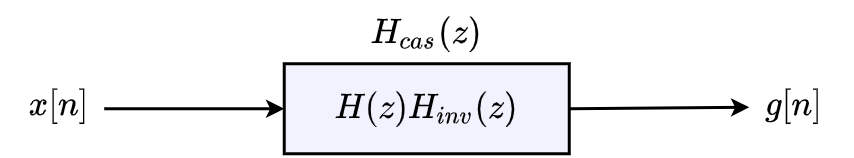

and it will have the following expression,


$$\begin{array}{l}
H_{\mathrm{cas}} \left(z\right)\;=\;H\left(z\right)H_{\mathrm{inv}} \left(z\right)\;=\;H\left(z\right)\frac{1}{H_{\min } \left(z\right)}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }\times \frac{{{\;\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)}^{-1} \;{\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)}^{-1} \;\left(1\ldotp 25\right)}^{-2} \;z^4 \;}{\left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{{\left(1\ldotp 25\right)}^2 \left(z-0\ldotp 8e^{-j\;0\ldotp 8\pi } \right)\left(z-0\ldotp 8e^{j\;0\ldotp 8\pi } \right)}
\end{array}$$


The code, along with results, to compute & plot various responses from $H_{\mathrm{cas}} \left(z\right)$ expression above, starts below.

% <task> plot magnitude and phase response of cascaded system Hcas(z)

% define z-domain expression for Hcas(z) = H(z).Hinv(z)
Hcasz = Hz*Hinvz;

% display Hcas(z) expression
disp('Hcas(z) = '); disp(vpa(Hcasz, 4))

Hcas(z) = 


$$\frac{\left(z+1.011-0.7347\,\mathrm{i}\right)\,\left(z+1.011+0.7347\,\mathrm{i}\right)\,\left(z+0.2781-0.856\,\mathrm{i}\right)}{\left(1.562\,z+0.4346-1.337\,\mathrm{i}\right)\,\left(z+0.6472-0.4702\,\mathrm{i}\right)\,\left(z+0.6472+0.4702\,\mathrm{i}\right)}$$

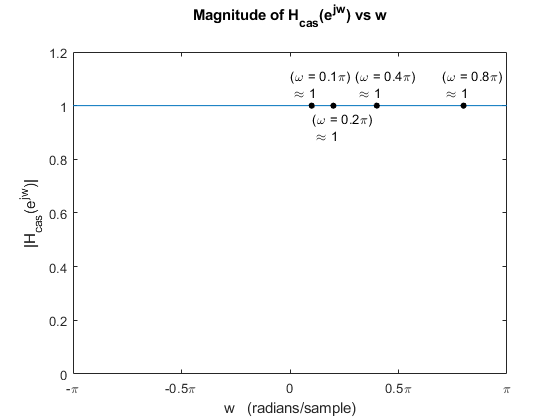


% obtain frequency response Hcas(w) expression from Hcas(z)
% by substituting z = e^(jw)
syms w_;
Hcasw = subs(Hcasz, {z}, {exp(1i*w_)});

% compute frequency response Hcas(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hcasw = subs(Hcasw, {w_}, {w});
Hcasw = double(Hcasw);

% obtain magnitude and phase of Hcas(w)
Hcasw_mag = abs(Hcasw);
Hcasw_arg = phase(Hcasw);           % unwrapped phase (in radians)
Hcasw_ARG = angle(Hcasw);           % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H_{cas}(e^{jw})|');
title({'Magnitude of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hcasw_mag, dw, -0.1*pi, [1 -1 1 1]*0.08, {'(\omega = ', '\pi)', ''}, pi);

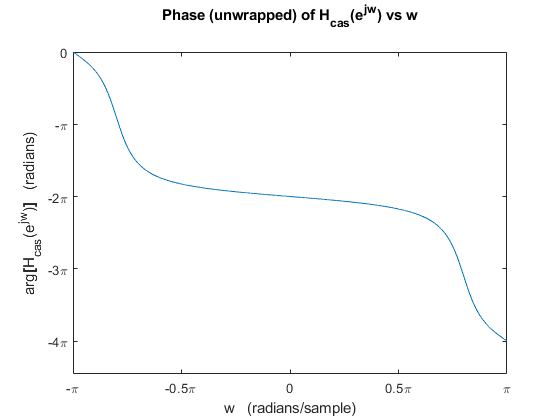


% plot phase (unwrapped) of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H_{cas}(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

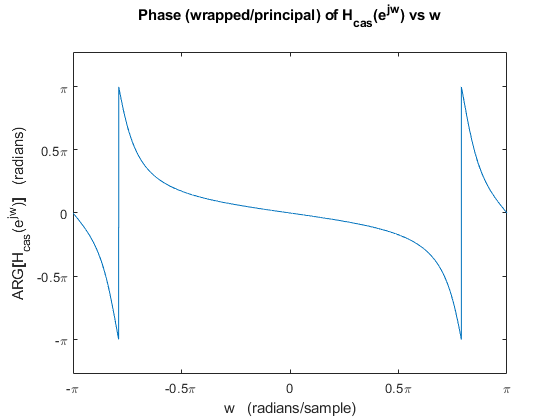


% plot phase (wrapped/principal) of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H_{cas}(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

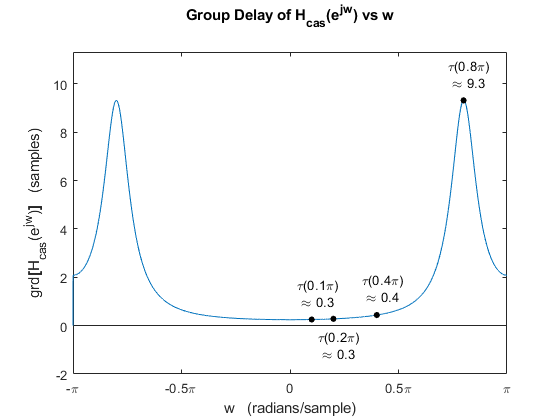


% <task> plot group-delay of given LTI system

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of Hcas(w)
Hcasw_grd = -([Hcasw_arg 0]-[0 Hcasw_arg])/dw;
Hcasw_grd = Hcasw_grd(1:(length(Hcasw_grd)-1));

% plot group-delay of Hcas(w) vs w
fig = figure; 
plot(w, Hcasw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H_{cas}(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H_{cas}(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hcasw_grd)-2 max(Hcasw_grd)+2]);
markOnPlot(wvals, w, Hcasw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);


% extract CCDE coefficients (b's and a's) from Hcas(z) expression
[N, D] = numden(Hcasz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    0.6400    1.2944    1.0000

a =
    1.0000    1.2944    0.6400



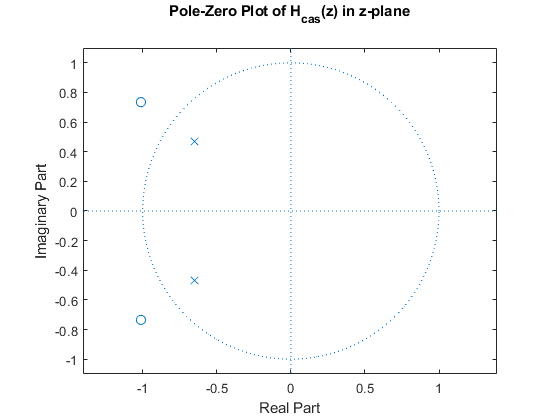


% plot the pole-zero map of Hcas(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H_{cas}(z) in z-plane';''});

The pole-zero map above matches with the z-domain expression $H_{\mathrm{cas}} \left(z\right)$ obtained at start of this section (Q5).

The magnitude plot $|H_{\mathrm{cas}} \left(e^{j\omega } \right)|$ (Page X) shows that the gain is a constant 1 at all frequencies, that is, $H_{\mathrm{cas}} \left(z\right)$ is an all-pass system. So, any input passed through the overall system experiences no magnitude distortion. Although, any input will experience phase-distortion (delay in samples) affecting different frequencies differently thereby distorting the signal shape at output.

**Question (6):**

How much delay do you observe corresponding to different $\omega_c$? Can you explain the delay in the output to the group delay of the overall system $H_{\textrm{cas}} \left(z\right)$ ($H\left(z\right)$ cascaded with its inverse).

**Answer (6):**

From the group-delay plot $\tau \left(\omega \right)=\mathrm{grd}\left\lbrack H_{\mathrm{cas}} \left(z\right)\right\rbrack$, the delays for specified $\omega_c$ values can be noted as follows:


$$\begin{array}{l}
\tau \left(\;\;\;0\ldotp 1\pi \;\;\mathrm{radians}/\mathrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\mathrm{samples}\;\mathrm{delay}\\
\tau \left(\;\;\;0\ldotp 2\pi \;\;\mathrm{radians}/\mathrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3\;\;\mathrm{samples}\;\mathrm{delay}\\
\tau \left(\;\;\;0\ldotp 4\pi \;\;\mathrm{radians}/\mathrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 4\;\;\mathrm{samples}\;\mathrm{delay}\\
\tau \left(\;\;\;0\ldotp 8\pi \;\;\mathrm{radians}/\mathrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;9\ldotp 3\;\;\mathrm{samples}\;\mathrm{delay}
\end{array}$$


The delay in $g\left\lbrack n\right\rbrack$